# **Inverse Mapping Artificial Neural Networks for Mechanical Ventilator Parameter Prediction using GPSO**

Sanjay Sarma O V

Inverse mapping is a procedure to obtain the right input parameter values for the ANNs for known outputs. This procedure is widely used in engineering applications, especially in kinematics of manipulators. In these problems, joint parameters are computed inversely for a given end effector’s position in space [8, 9, 10]. In our case, we introduce a population based optimization algorithm in the feedback loop which corrects and estimates the inputs for a desired patient output. We name our algorithm Graded – Particle Swarm Optimization, which is a variant of the famous Particle Swarm Optimization [11]. The schematic of the invere mapping model in our current work is presented in figure 1.

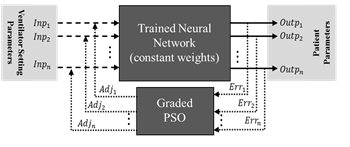

***Fig. 1 Closed Loop system for inverse mapping artificial neural networks***

Graded PSO in contrast to regular PSO, equally divides the swarm into ‘N-groups.’ A hierarchical group (N+1) is generated with all the group leaders combined. This hierarchical group is headed by a universal leader. For this new scenario, we propose a new set of equations with additional, where each individual is influenced by its personal, group and universal leader’s behaviors. In the current paper, we introduce the Graded PSO technique in the next section, followed by the detailing on the training of NN functions and inverse mapping of NN functions. In the end we present the results obtained for few test condition. For our current work, we collected data from an ongoing study at University of Georgia – Small Animal Teaching Hospital for canines and felines.

## **Graded Particle Swarm Optimization (GPSO) **

    Ever since the introduction of Particle Swarm Optimization (PSO) by Kennedy and Eberhart [11], it has found many applications in the areas of control systems, signal processing, optimization and machine learning, where ever a complex, non-linear optimization is involved. PSO works on a real number space, is quicker and easy to implement in comparison to other swarm and computational intelligence (CI) techniques. However, the convergence at global optima is not guaranteed for all complex fitness functions, which also is true for the other CI techniques. In order to address such issues, many variants were proposed over the past decade, which also focus on achieving quicker and higher probability of convergence apart from achieving the optima [12]. Recent variants include a subpopulation swarm strategy by Wei Der Chang et al., [12] presents individual groups searching for local optimum in a divided search space. Yen et al., [13] proposed particle exchange between sub groups after a fixed number of iterations. Another recent variant Clubs based PSO [14], maintains a dynamic membership strategy by grouping and regrouping of particles based on their relative performance. We present a complete analysis and comparison of GPSO with clubs based PSO and regular PSO on standard test functions in [our previous work [16].](http://ieeexplore.ieee.org/document/7893404/)

A widely-used variant of PSO is with an additional momentum factor included in the equations. The general position and velocity update equations for each particle are as per (1) and (2).

${\mathrm{v}}_{\mathrm{i}}^{\mathrm{t}+1} ={\omega \ldotp \mathrm{v}}_{\mathrm{i}}^{\mathrm{t}} +{\mathrm{r}}_1 \ldotp {\mathrm{c}}_1 \ldotp {\left(\mathrm{p}\mathrm{b}\mathrm{e}\mathrm{s}{\mathrm{t}}_{\mathrm{i}}^{\mathrm{t}} -{\mathrm{x}}_{\mathrm{i}}^{\mathrm{t}} \right)}+{\mathrm{r}}_2 \ldotp {\mathrm{c}}_2 \ldotp {\left(\mathrm{g}\mathrm{b}\mathrm{e}\mathrm{s}{\mathrm{t}}^{\mathrm{t}} -{\mathrm{x}}_{\mathrm{i}}^{\mathrm{t}} \right)}$     ** (1)**

${\mathrm{x}}_{\mathrm{i}}^{\mathrm{t}+1} ={\mathrm{x}}_{\mathrm{i}}^{\mathrm{t}} +{\mathrm{v}}_{\mathrm{i}}^{\mathrm{t}+1}$  **(2)**


$$\textrm{Where},v_{i\;} \;\textrm{and}{\;x}_{i\;} \;\textrm{are}\;\textrm{the}\;\textrm{velocity}\;\textrm{and}\;\textrm{position}\;\textrm{values}\;\textrm{of}\;\textrm{the}{\;i}^{\textrm{th}} \;\textrm{particle}\;\textrm{in}{\;t}^{\textrm{th}} \;\textrm{dimension}\;\textrm{and}\;\textrm{with}\;\textrm{in}\;a\;\textrm{total}\;\textrm{population}\;\textrm{size}\;\textrm{of}\;m\ldotp {\textrm{pbest}}_i^t \;\textrm{is}\;\textrm{the}\;\textrm{best}\;\textrm{position}\;\textrm{of}\;\textrm{the}{\;i}^{\textrm{th}} \;\textrm{particle}\;\textrm{so}\;\textrm{far}\;\textrm{and}\;{\textrm{gbest}}^{t\;} \textrm{is}\textrm{the}\textrm{global}\textrm{best}\ldotp r_1 ,r_2 \;\textrm{are}\textrm{the}\textrm{random}\textrm{numbers}\textrm{between}\left\lbrack 0\;1\right\rbrack \;\textrm{and}\;c_1 \;,c_2 \textrm{are}\;\textrm{the}\;\textrm{cognitive}\;\textrm{and}\;\textrm{social}\textrm{factors}\;\textrm{respectively}\ldotp$$


In our proposed variant, we introduce an additional universal term in the velocity update equation as in (3). The definition for  is the same as in regular PSO, whereas the definition of  is now changed to , which is termed as the group’s best (group and  dimension) instead of global best as in the regular PSO. Further, a new constant  is introduced weighing the influence of universal leader. It can be observed that as per equation (3), each particle’s motion in any dimension is a resultant of the vectors corresponding to its personal, group and universal best values. 

${\mathrm{v}}_{\mathrm{i}}^{\mathrm{t}+1} ={\omega \ldotp \mathrm{v}}_{\mathrm{i}}^{\mathrm{t}} +{\mathrm{r}}_1 \ldotp {\mathrm{c}}_1 \ldotp {\left(\mathrm{p}\mathrm{b}\mathrm{e}\mathrm{s}{\mathrm{t}}_{\mathrm{i}}^{\mathrm{t}} -{\mathrm{x}}_{\mathrm{i}}^{\mathrm{t}} \right)}+{\mathrm{r}}_2 \ldotp {\mathrm{c}}_2 \ldotp {\left(\mathrm{g}\mathrm{b}\mathrm{e}\mathrm{s}{\mathrm{t}}_{\mathrm{n}}^{\mathrm{t}} -{\mathrm{x}}_{\mathrm{i}}^{\mathrm{t}} \right)}+{\mathrm{r}}_3 \ldotp {\mathrm{c}}_3 {\left(\mathrm{u}\mathrm{b}\mathrm{e}\mathrm{s}{\mathrm{t}}^{\mathrm{t}} -{\mathrm{x}}_{\mathrm{i}}^{\mathrm{t}} \right)}\;\;\;$**(3)**

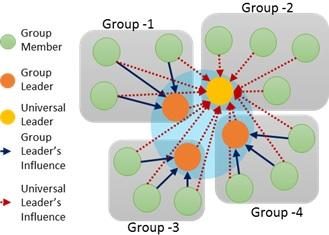 

***Fig.2 Grouping and the influence of leader on a particle in GPSO***

## **Data and Experimentation**

The current study retrospectively examined data from 24 patients of Small Animal Veterinary Teaching Hospital at University of Georgia College of Veterinary Medicine. Data of canines and felines subjected to mechanical ventilation was considered. Patients were classified into either having healthy or unhealthy lungs and the data from ventilators along with physical parameters were collected over time. Six of the patients were classified as having healthy lungs and were ventilated to treat hypoventilation arising from such disorders as lower motor neuron disease, cervical spinal myelopathy, and drug toxicity. And 18 animals were classified as having unhealthy lungs and were ventilated to treat hypoxemia caused by disorders such as congestive heart failure, pneumonia, and contusions. 

All the animals were anesthetized, most often with infusions of Propofol and Fentanyl, orotracheally intubated and mechanically ventilated using pressure-controlled ventilation in SIMV mode. All ventilation was conducted using the Respironics Esprit ventilator and monitoring data was obtained using the NICO monitor.

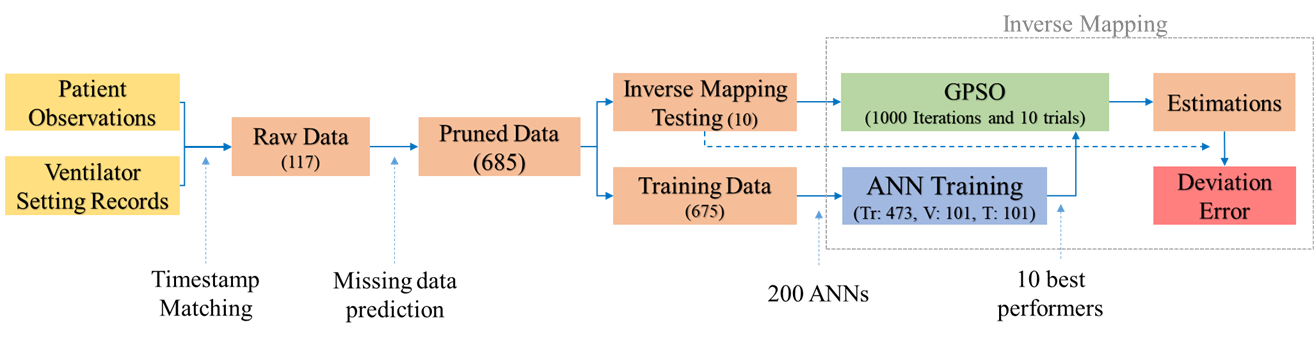

winopen PatientData.xlsx

## 1. Preprocessing

### *1.a*    *Data Pruning and Segregation*

The data used for our current study contained both physical observations and the data logged from the ventilator which had definite time stamps. Set pressure (SetP), Peak Input Pressure (PIP), Positive End Expiratory Pressure (PEEP), Pressure Support Ventilation (PSV), Respiratory Rate (RR) and Fraction of Inspired Oxygen (FiO2) were considered as inputs. While, Tidal Volume (Vti), Dynamic Compliance (Cydn), End Tidal CO2 (EtCo2), Blood Oxygen Saturation (SpO2), Heart Rate (HR), Blood Pressure (BP) and Temperature as output parameters for the model. However, many missing data fields were identified in the patient observations as they were sporadic observations and hence, we used an ANN based prediction for these missing data points. 

For, predicting these missing data points, multiple ANNs were trained using observations with complete data fields as inputs and the missing fields as output for the data. For example, an observation with missing data point for Vti is predicted using an ANN trained with Vti as output and the remaining parameters other than Vti as inputs. And now the observations with missing Vti were predicted with the remaining fields as input to this artificial neural network. While predicting these missing data points, the values exceeding the limits of the known data were truncated to the nearest maximum or minimum values from the complete data sets. This enhanced our number of observations from 117 to 685 data points.

               Further, this pruned data was segregated into two sets for our inverse mapping model. The first set included the data for training, validating and testing ANNs for forward prediction and the second set was used for testing inverse mapping process. The selection of data was completely random.

***The following code separates the patient information from the excel sheets and stores in a matfile***

Note: This is specific to the current problem and may be modified for other data sets



clc;
clear all;
close all;
[FileName, PathName]= uigetfile('.xlsx');
% Prompts for number of sheets to read from the source file. Enter 20 for all the files to be read.
totalPatients=input('Enter Number of Patients/Sheets to Read:\n');   
ctr=1;
for sht=1:totalPatients
    clear Nums Txt;
    [Numsraw,Txt]=xlsread(strcat(PathName,FileName),sht);
    matName=strcat('Data_',num2str(sht));
    eval(strcat(matName,'.Type=','''',char(Txt(1,2)),''';'));
    eval(strcat(matName,'.Breed=','''',char(Txt(2,2)),''';'));
    eval(strcat(matName,'.Gender=','''',char(Txt(4,2)),''';'));
    Nums=Numsraw(5:end,:);
    DataRaw.Weight=Numsraw(1,2);
    DataRaw.Age=Numsraw(2,2);
    DataRaw.SetP=Nums(:,3);
    DataRaw.ActPIP=Nums(:,4);
    DataRaw.PEEP=Nums(:,5);
    DataRaw.PSV=Nums(:,6);
    DataRaw.ActRR=Nums(:,7);
    DataRaw.SetRR=Nums(:,8);
    DataRaw.FiO2=Nums(:,9);
    DataRaw.Vti=Nums(:,10);
    DataRaw.Cdyn=Nums(:,11);
    DataRaw.EtCo2=Nums(:,12);
    DataRaw.SpO2=Nums(:,13);
    DataRaw.HR=Nums(:,14);
    DataRaw.BP=Nums(:,15);
    DataRaw.Temp=Nums(:,16);
    DataRaw.Health=Nums(:,18);
    eval([strcat(matName,'.DataRaw=DataRaw;')]);  
    eval([strcat('DataProcess.Patients.s',num2str(sht),'=',matName,';')]);
    sz=size(Nums);
    weightMat= repmat(DataRaw.Weight,sz(1),1);
    ageMat=repmat(DataRaw.Age,sz(1),1);
    if ctr==1
        dumMat=[weightMat ageMat Nums(:,3:15) Nums(:,17)];
    else
        dumMat=[dumMat; weightMat ageMat Nums(:,3:15) Nums(:,17)];
    end
    ctr=ctr+1;
end
DataProcess.rawDataAll=dumMat;
save('MasterDataSet.mat');

***The separated mat file is combined to form a single data set***

% This portion is already executed. Executing again might corrmpt some data
clc;
clear all; 
close all;
load('MasterDataSet.mat');
    % Enter total number of patients data to be processed here
for i=1:totalPatients
   eval([strcat('dumVar=Data_',num2str(i),';')]);
   dtLn=length(dumVar.DataRaw.EtCo2);
   age=repmat(dumVar.DataRaw.Age,dtLn,1);
   weight=repmat(dumVar.DataRaw.Weight,dtLn,1);
 if i==1
        combinedMat=[age weight dumVar.DataRaw.SetP dumVar.DataRaw.PEEP dumVar.DataRaw.PSV...
        dumVar.DataRaw.ActRR dumVar.DataRaw.SetRR dumVar.DataRaw.FiO2 dumVar.DataRaw.Vti...
        dumVar.DataRaw.Cdyn dumVar.DataRaw.EtCo2 dumVar.DataRaw.SpO2 dumVar.DataRaw.HR...
        dumVar.DataRaw.BP dumVar.DataRaw.Temp];
 else
        combinedMat=[combinedMat; age weight dumVar.DataRaw.SetP dumVar.DataRaw.PEEP dumVar.DataRaw.PSV...
        dumVar.DataRaw.ActRR dumVar.DataRaw.SetRR dumVar.DataRaw.FiO2 dumVar.DataRaw.Vti...
        dumVar.DataRaw.Cdyn dumVar.DataRaw.EtCo2 dumVar.DataRaw.SpO2 dumVar.DataRaw.HR...
        dumVar.DataRaw.BP dumVar.DataRaw.Temp];
    
 end
end

save('CombinedData.mat','combinedMat');

### **1.b Missing Data Prediction**

Note: This segments take very long time to execute.

% This portion is already executed. Executing again might corrmpt some data. Also it takes too long as the data values should go through various NNs
clc
clear;
close all;
load('CombinedData.mat')
ln=length(combinedMat);
complData=combinedMat(~any(isnan(combinedMat),2),:)

complData =     1.0000    1.9000   15.0000    5.0000    5.0000   17.0000   17.0000   60.0000   46.0000    3.0000   31.0000   94.0000   94.0000  160.0000   97.2000
    1.0000    1.9000   15.0000    6.0000    5.0000   20.0000   17.0000   60.0000   35.0000    3.0000   39.0000   93.0000   78.0000  160.0000   99.5000
    1.0000    1.9000   13.0000    6.0000    5.0000  112.0000   17.0000   50.0000   24.0000    2.0000   32.0000   94.0000   91.0000   75.0000   99.3000
    1.0000    1.9000   13.0000    7.0000    5.0000   52.0000   17.0000    5.0000   25.0000    5.0000   37.0000   92.0000   93.0000  125.0000   99.7000
    1.0000    1.9000   13.0000    7.0000    5.0000   21.0000   17.0000   50.0000   22.0000    3.0000   46.0000   92.0000  110.0000  135.0000  100.6000
    1.0000    1.9000   14.0000    7.0000    5.0000   24.0000   22.0000   50.0000   22.0000    3.0000   42.0000   91.0000   93.0000  135.0000  100.0000
    1.0000    1.9000   14.0000    7.0000    5.0000   25.0000   24.0000   50.0000  

sz=size(combinedMat);
combinedMatPred=combinedMat;
ln=sz(1);
maxLim=max(complData,[],1);
minLim=min(complData,[],1);
for rwCtr=1:ln
   disp(strcat(num2str(rwCtr),'/',num2str(ln)))
   currData=combinedMat(rwCtr,:);
   chkLocs=isnan(currData);
   if sum(chkLocs)~=0
      inptClms= find(~chkLocs);
      outptClms=find(chkLocs);
      inptData= complData(:,inptClms);
      outptData=complData(:,outptClms);
      netSize=[sum(~chkLocs) 2*sum(~chkLocs) 2*sum(chkLocs) ];
      genNetwork(inptData,outptData,netSize);
      % Generate Output
      currInp=currData(:,inptClms);
      currOutpReal=round(currNetwork(currInp'));
      currOutp=currOutpReal;
      cmpMax=maxLim(1,outptClms);
      cmpMin=minLim(1,outptClms);
      for j=1:length(currOutp)
          if currOutp(j)>cmpMax(j)
              currOutp(j)=cmpMax(j);
          elseif currOutp(j)<cmpMin(j)
              currOutp(j)=cmpMin(j);
          end
      end
     currDataPred=currData;
     currDataPred(:,outptClms)=currOutp;
     [currData;currDataPred]
     combinedMatPred(rwCtr,:)=currDataPred;
    end
 end

1/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 703.5481

trainPerformance = 683.4631

valPerformance = 622.8963

testPerformance = 874.5819

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     1.0000    1.9000   15.0000    5.0000    5.0000   80.0000   20.0000   80.0000       NaN       NaN   36.0000   99.0000   89.0000       NaN   92.7000
    1.0000    1.9000   15.0000    5.0000    5.0000   80.0000   20.0000   80.0000   39.0000   32.0000   36.0000   99.0000   89.0000  136.0000   92.7000


2/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 270.5134

trainPerformance = 240.9440

valPerformance = 324.2036

testPerformance = 349.8854

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     1.0000    1.9000       NaN       NaN       NaN   80.0000   20.0000   80.0000       NaN       NaN   34.0000   96.0000   84.0000       NaN   93.2000
    1.0000    1.9000   18.0000    2.0000   12.0000   80.0000   20.0000   80.0000   43.0000    4.0000   34.0000   96.0000   84.0000  132.0000   93.2000


3/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.0222e+03

trainPerformance = 1.0275e+03

valPerformance = 883.3005

testPerformance = 1.1370e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     1.0000    1.9000   15.0000    5.0000    5.0000  100.0000   25.0000  100.0000       NaN    3.0000   32.0000   96.0000  124.0000       NaN   94.3000
    1.0000    1.9000   15.0000    5.0000    5.0000  100.0000   25.0000  100.0000   18.0000    3.0000   32.0000   96.0000  124.0000  120.0000   94.3000


4/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 488.4235

trainPerformance = 463.0283

valPerformance = 437.6998

testPerformance = 653.4260

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     1.0000    1.9000   15.0000    5.0000    5.0000   97.0000   25.0000  100.0000       NaN    4.0000   41.0000   98.0000   86.0000       NaN   95.7000
    1.0000    1.9000   15.0000    5.0000    5.0000   97.0000   25.0000  100.0000   58.0000    4.0000   41.0000   98.0000   86.0000  112.0000   95.7000


5/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 244.8336

trainPerformance = 140.2907

valPerformance = 476.6177

testPerformance = 483.4927

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     1.0000    1.9000   15.0000    5.0000    5.0000   25.0000   25.0000   80.0000       NaN       NaN   32.0000   98.0000   66.0000  150.0000   96.3000
    1.0000    1.9000   15.0000    5.0000    5.0000   25.0000   25.0000   80.0000   27.0000    7.0000   32.0000   98.0000   66.0000  150.0000   96.3000


6/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 527.7000

trainPerformance = 269.5354

valPerformance = 817.8490

testPerformance = 1.3993e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     1.0000    1.9000   15.0000    5.0000    5.0000    8.0000   20.0000   60.0000       NaN       NaN   27.0000   98.0000   94.0000  160.0000   96.4000
    1.0000    1.9000   15.0000    5.0000    5.0000    8.0000   20.0000   60.0000   33.0000    5.0000   27.0000   98.0000   94.0000  160.0000   96.4000


7/685
8/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 449.6614

trainPerformance = 205.3954

valPerformance = 122.0523

testPerformance = 1.8765e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     1.0000    1.9000   15.0000    5.0000    5.0000   17.0000   17.0000   60.0000   41.0000       NaN   36.0000   92.0000   53.0000  175.0000   98.1000
    1.0000    1.9000   15.0000    5.0000    5.0000   17.0000   17.0000   60.0000   41.0000   21.0000   36.0000   92.0000   53.0000  175.0000   98.1000


9/685
10/685
11/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 173.0770

trainPerformance = 152.1881

valPerformance = 208.6605

testPerformance = 231.4935

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     1.0000    1.9000   14.0000    6.0000    5.0000   32.0000   17.0000   40.0000   38.0000    2.0000   39.0000   93.0000       NaN       NaN       NaN
    1.0000    1.9000   14.0000    6.0000    5.0000   32.0000   17.0000   40.0000   38.0000    2.0000   39.0000   93.0000   89.0000  144.0000   97.0000


12/685
13/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 223.2210

trainPerformance = 184.5154

valPerformance = 254.4679

testPerformance = 366.1492

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     1.0000    1.9000   13.0000    7.0000    5.0000   38.0000   17.0000   50.0000   21.0000    3.0000   38.0000   91.0000       NaN       NaN       NaN
    1.0000    1.9000   13.0000    7.0000    5.0000   38.0000   17.0000   50.0000   21.0000    3.0000   38.0000   91.0000   80.0000  132.0000  103.3000


14/685
15/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 229.7926

trainPerformance = 207.4317

valPerformance = 293.1742

testPerformance = 267.0350

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     1.0000    1.9000   13.0000    7.0000    5.0000   31.0000   30.0000   60.0000   23.0000    3.0000   38.0000   92.0000       NaN       NaN       NaN
    1.0000    1.9000   13.0000    7.0000    5.0000   31.0000   30.0000   60.0000   23.0000    3.0000   38.0000   92.0000  100.0000  160.0000  100.0000


16/685
17/685
18/685
19/685
20/685
21/685
22/685
23/685
24/685
25/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 252.2550

trainPerformance = 146.8778

valPerformance = 570.6237

testPerformance = 408.0838

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     1.0000    1.9000   13.0000    7.0000    6.0000   60.0000   28.0000  100.0000   31.0000    3.0000   42.0000   91.0000  124.0000       NaN   99.1000
    1.0000    1.9000   13.0000    7.0000    6.0000   60.0000   28.0000  100.0000   31.0000    3.0000   42.0000   91.0000  124.0000  163.0000   99.1000


26/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 303.0540

trainPerformance = 241.8574

valPerformance = 160.7063

testPerformance = 720.7866

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     1.0000    1.9000   13.0000    7.0000    8.0000   85.0000   20.0000   60.0000   22.0000    3.0000   40.0000   88.0000  146.0000       NaN  100.8000
    1.0000    1.9000   13.0000    7.0000    8.0000   85.0000   20.0000   60.0000   22.0000    3.0000   40.0000   88.0000  146.0000  141.0000  100.8000


27/685
28/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 298.5728

trainPerformance = 233.6226

valPerformance = 324.6659

testPerformance = 564.7558

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     1.0000    1.9000   13.0000    7.0000    8.0000   46.0000   20.0000   70.0000   19.0000    4.0000   32.0000   80.0000       NaN       NaN       NaN
    1.0000    1.9000   13.0000    7.0000    8.0000   46.0000   20.0000   70.0000   19.0000    4.0000   32.0000   80.0000  120.0000  145.0000   96.0000


29/685
30/685
31/685
32/685
33/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 679.2959

trainPerformance = 638.9901

valPerformance = 596.0828

testPerformance = 943.8852

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     1.0000    1.9000       NaN       NaN       NaN  111.0000   25.0000   60.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    1.0000    1.9000   19.0000    5.0000    6.0000  111.0000   25.0000   60.0000   42.0000   21.0000   29.0000   71.0000  109.0000  142.0000  101.0000


34/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 323.6020

trainPerformance = 314.2042

valPerformance = 400.7361

testPerformance = 288.7582

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =      6    43     7     3     5     8     8    80   445   NaN    37    93   NaN   120   NaN
     6    43     7     3     5     8     8    80   445    89    37    93    60   120    80


35/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 468.4105

trainPerformance = 238.5231

valPerformance = 233.7371

testPerformance = 1.7376e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    7.0000    3.0000    5.0000    9.0000    9.0000   80.0000  429.0000       NaN   52.0000   95.0000       NaN  130.0000   98.7000
    6.0000   43.0000    7.0000    3.0000    5.0000    9.0000    9.0000   80.0000  429.0000   83.0000   52.0000   95.0000   93.0000  130.0000   98.7000


36/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 27.4084

trainPerformance = 3.2950

valPerformance = 3.1872

testPerformance = 160.1396

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    7.0000    3.0000    5.0000   10.0000   10.0000   50.0000  514.0000       NaN   37.0000  100.0000  132.0000  148.0000   97.2000
    6.0000   43.0000    7.0000    3.0000    5.0000   10.0000   10.0000   50.0000  514.0000  110.0000   37.0000  100.0000  132.0000  148.0000   97.2000


37/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 515.5864

trainPerformance = 681.9145

valPerformance = 131.7406

testPerformance = 150.9560

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    7.0000    3.0000    5.0000   12.0000   12.0000   40.0000  403.0000       NaN   37.0000   95.0000  125.0000  129.0000   97.5000
    6.0000   43.0000    7.0000    3.0000    5.0000   12.0000   12.0000   40.0000  403.0000   31.0000   37.0000   95.0000  125.0000  129.0000   97.5000


38/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 495.5469

trainPerformance = 38.3227

valPerformance = 647.4437

testPerformance = 2.4012e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    8.0000    3.0000    5.0000   13.0000   13.0000   40.0000  424.0000       NaN   36.0000   96.0000  129.0000  139.0000   98.4000
    6.0000   43.0000    8.0000    3.0000    5.0000   13.0000   13.0000   40.0000  424.0000   37.0000   36.0000   96.0000  129.0000  139.0000   98.4000


39/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 188.8565

trainPerformance = 44.3965

valPerformance = 15.1612

testPerformance = 1.0126e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =      6    43     9     3     5    13    13    40   512   NaN    37    96    85   126    99
     6    43     9     3     5    13    13    40   512    35    37    96    85   126    99


40/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 228.9415

trainPerformance = 219.6178

valPerformance = 131.4008

testPerformance = 368.4393

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =      6    43     9     3     5    15    15    35   449   NaN    42   100    87   116   100
     6    43     9     3     5    15    15    35   449    63    42   100    87   116   100


41/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 790.9430

trainPerformance = 1.0186e+03

valPerformance = 247.7478

testPerformance = 309.7692

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000   20.0000    3.0000    5.0000   15.0000   15.0000   35.0000  508.0000       NaN   40.0000  100.0000   79.0000  105.0000   99.9000
    6.0000   43.0000   20.0000    3.0000    5.0000   15.0000   15.0000   35.0000  508.0000  106.0000   40.0000  100.0000   79.0000  105.0000   99.9000


42/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.3743e+03

trainPerformance = 1.6639e+03

valPerformance = 135.0715

testPerformance = 1.3104e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    9.0000    2.0000    5.0000   13.0000   13.0000   35.0000  439.0000       NaN   42.0000  100.0000   77.0000  108.0000   99.7000
    6.0000   43.0000    9.0000    2.0000    5.0000   13.0000   13.0000   35.0000  439.0000   59.0000   42.0000  100.0000   77.0000  108.0000   99.7000


43/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 50.4993

trainPerformance = 59.4893

valPerformance = 8.5557

testPerformance = 51.9879

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    8.0000    2.0000    5.0000   14.0000   14.0000   35.0000  374.0000       NaN   43.0000  100.0000  118.0000  110.0000   99.3000
    6.0000   43.0000    8.0000    2.0000    5.0000   14.0000   14.0000   35.0000  374.0000   48.0000   43.0000  100.0000  118.0000  110.0000   99.3000


44/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.0706e+03

trainPerformance = 1.4328e+03

valPerformance = 348.7004

testPerformance = 162.7898

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    8.0000    2.0000    5.0000   14.0000   14.0000   35.0000  441.0000       NaN   42.0000   99.0000   83.0000  118.0000   98.8000
    6.0000   43.0000    8.0000    2.0000    5.0000   14.0000   14.0000   35.0000  441.0000  101.0000   42.0000   99.0000   83.0000  118.0000   98.8000


45/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 61.0493

trainPerformance = 55.5639

valPerformance = 20.4051

testPerformance = 126.3777

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    8.0000    2.0000    5.0000   12.0000   12.0000   30.0000  411.0000       NaN   40.0000   99.0000  156.0000  102.0000   99.1000
    6.0000   43.0000    8.0000    2.0000    5.0000   12.0000   12.0000   30.0000  411.0000   61.0000   40.0000   99.0000  156.0000  102.0000   99.1000


46/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 2.1263e+03

trainPerformance = 1.4898e+03

valPerformance = 186.7738

testPerformance = 6.9299e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    7.0000    2.0000    5.0000   10.0000   10.0000   30.0000  375.0000       NaN   52.0000   98.0000  151.0000  133.0000   99.7000
    6.0000   43.0000    7.0000    2.0000    5.0000   10.0000   10.0000   30.0000  375.0000   27.0000   52.0000   98.0000  151.0000  133.0000   99.7000


47/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 371.1156

trainPerformance = 108.9216

valPerformance = 1.4450e+03

testPerformance = 477.0828

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =      6    43     7     2     5    14     4    30   314   NaN    63    96   139   125   100
     6    43     7     2     5    14     4    30   314    66    63    96   139   125   100


48/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 159.6342

trainPerformance = 190.4665

valPerformance = 121.8821

testPerformance = 58.6406

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    7.0000    2.0000    5.0000   10.0000   10.0000   30.0000  280.0000       NaN   63.0000   93.0000  173.0000  188.0000  100.6000
    6.0000   43.0000    7.0000    2.0000    5.0000   10.0000   10.0000   30.0000  280.0000   76.0000   63.0000   93.0000  173.0000  188.0000  100.6000


49/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 738.5441

trainPerformance = 443.1391

valPerformance = 153.4715

testPerformance = 2.6529e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    8.0000    2.0000    5.0000   23.0000    7.0000   30.0000  428.0000       NaN   62.0000   96.0000  169.0000  102.0000  100.9000
    6.0000   43.0000    8.0000    2.0000    5.0000   23.0000    7.0000   30.0000  428.0000   21.0000   62.0000   96.0000  169.0000  102.0000  100.9000


50/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 2.0355e+03

trainPerformance = 2.8108e+03

valPerformance = 201.1615

testPerformance = 381.0915

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    8.0000    2.0000    5.0000   15.0000   10.0000   30.0000  431.0000       NaN   64.0000   98.0000  156.0000  104.0000  100.8000
    6.0000   43.0000    8.0000    2.0000    5.0000   15.0000   10.0000   30.0000  431.0000   41.0000   64.0000   98.0000  156.0000  104.0000  100.8000


51/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 137.1480

trainPerformance = 129.4582

valPerformance = 55.2556

testPerformance = 253.6446

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    8.0000    2.0000    5.0000   10.0000   10.0000   30.0000  424.0000       NaN   63.0000   99.0000  146.0000  106.0000  100.4000
    6.0000   43.0000    8.0000    2.0000    5.0000   10.0000   10.0000   30.0000  424.0000   30.0000   63.0000   99.0000  146.0000  106.0000  100.4000


52/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 377.5562

trainPerformance = 427.0768

valPerformance = 125.3160

testPerformance = 406.9538

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    8.0000    2.0000    5.0000   24.0000   15.0000   30.0000  380.0000       NaN   57.0000   97.0000  168.0000  100.0000  100.4000
    6.0000   43.0000    8.0000    2.0000    5.0000   24.0000   15.0000   30.0000  380.0000   77.0000   57.0000   97.0000  168.0000  100.0000  100.4000


53/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 530.9344

trainPerformance = 492.4885

valPerformance = 38.4859

testPerformance = 1.1964e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =      6    43     7     2     5    15    15    30   376   NaN    57    98   166   120   100
     6    43     7     2     5    15    15    30   376    54    57    98   166   120   100


54/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 283.6405

trainPerformance = 51.6750

valPerformance = 1.3573e+03

testPerformance = 253.8258

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =      6    43     7     2     5    15    15    30   351   NaN    56    97   152   137   100
     6    43     7     2     5    15    15    30   351    50    56    97   152   137   100


55/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 786.6745

trainPerformance = 135.6301

valPerformance = 166.1785

testPerformance = 4.3369e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =      6    43     8     2     5    15    15    30   374   NaN    54    98   125   134   100
     6    43     8     2     5    15    15    30   374    40    54    98   125   134   100


56/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.2295e+03

trainPerformance = 173.5482

valPerformance = 1.0573e+03

testPerformance = 6.1534e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    8.0000    2.0000    5.0000   15.0000   15.0000   30.0000  397.0000       NaN   55.0000   98.0000  135.0000  132.0000   99.7000
    6.0000   43.0000    8.0000    2.0000    5.0000   15.0000   15.0000   30.0000  397.0000   21.0000   55.0000   98.0000  135.0000  132.0000   99.7000


57/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 668.0313

trainPerformance = 823.4883

valPerformance = 77.2288

testPerformance = 559.2771

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000   10.0000    2.0000    8.0000   15.0000   15.0000   40.0000  397.0000       NaN   56.0000   98.0000  152.0000  122.0000   99.7000
    6.0000   43.0000   10.0000    2.0000    8.0000   15.0000   15.0000   40.0000  397.0000   51.0000   56.0000   98.0000  152.0000  122.0000   99.7000


58/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.7519e+03

trainPerformance = 2.2624e+03

valPerformance = 761.1460

testPerformance = 445.2639

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    9.0000    2.0000    8.0000   15.0000   15.0000   40.0000  471.0000       NaN   60.0000   98.0000  147.0000  119.0000   99.7000
    6.0000   43.0000    9.0000    2.0000    8.0000   15.0000   15.0000   40.0000  471.0000   48.0000   60.0000   98.0000  147.0000  119.0000   99.7000


59/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 772.4977

trainPerformance = 132.1601

valPerformance = 4.0532e+03

testPerformance = 373.2711

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    9.0000    3.0000    8.0000   15.0000   15.0000   40.0000  460.0000       NaN   59.0000  100.0000  141.0000  135.0000   99.5000
    6.0000   43.0000    9.0000    3.0000    8.0000   15.0000   15.0000   40.0000  460.0000   32.0000   59.0000  100.0000  141.0000  135.0000   99.5000


60/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 335.9190

trainPerformance = 466.5530

valPerformance = 42.5308

testPerformance = 41.4539

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    9.0000    3.0000    8.0000   15.0000   15.0000   30.0000  458.0000       NaN   54.0000   98.0000  120.0000  127.0000   99.1000
    6.0000   43.0000    9.0000    3.0000    8.0000   15.0000   15.0000   30.0000  458.0000  126.0000   54.0000   98.0000  120.0000  127.0000   99.1000


61/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 90.7022

trainPerformance = 117.1967

valPerformance = 22.8427

testPerformance = 39.3364

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    9.0000    3.0000    8.0000   15.0000   15.0000   30.0000  477.0000       NaN   52.0000  100.0000  118.0000  149.0000   99.3000
    6.0000   43.0000    9.0000    3.0000    8.0000   15.0000   15.0000   30.0000  477.0000   33.0000   52.0000  100.0000  118.0000  149.0000   99.3000


62/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 253.5638

trainPerformance = 242.4978

valPerformance = 38.7129

testPerformance = 518.2115

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    8.0000    4.0000    8.0000   12.0000   12.0000   40.0000  438.0000       NaN   54.0000   97.0000  157.0000  112.0000   99.3000
    6.0000   43.0000    8.0000    4.0000    8.0000   12.0000   12.0000   40.0000  438.0000  288.0000   54.0000   97.0000  157.0000  112.0000   99.3000


63/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 442.6397

trainPerformance = 509.8896

valPerformance = 271.1588

testPerformance = 311.4958

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    8.0000    3.0000    8.0000   12.0000   12.0000   40.0000  459.0000       NaN   49.0000   98.0000  134.0000  121.0000   99.5000
    6.0000   43.0000    8.0000    3.0000    8.0000   12.0000   12.0000   40.0000  459.0000   31.0000   49.0000   98.0000  134.0000  121.0000   99.5000


64/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 2.0848e+03

trainPerformance = 1.0163e+03

valPerformance = 2.0410e+03

testPerformance = 6.9369e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    6.0000    3.0000    5.0000   17.0000    8.0000   40.0000  358.0000       NaN   43.0000   96.0000  159.0000  129.0000   99.7000
    6.0000   43.0000    6.0000    3.0000    5.0000   17.0000    8.0000   40.0000  358.0000   30.0000   43.0000   96.0000  159.0000  129.0000   99.7000


65/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 496.9260

trainPerformance = 490.7012

valPerformance = 458.1771

testPerformance = 563.6865

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     6.0000   43.0000    8.0000    3.0000    5.0000   15.0000   12.0000   30.0000  499.0000       NaN   56.0000   99.0000  170.0000  107.0000   99.7000
    6.0000   43.0000    8.0000    3.0000    5.0000   15.0000   12.0000   30.0000  499.0000   23.0000   56.0000   99.0000  170.0000  107.0000   99.7000


66/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 191.7687

trainPerformance = 107.2760

valPerformance = 463.0631

testPerformance = 300.6913

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000   20.0000       NaN   10.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN  112.0000  120.0000  100.9000
   13.0000   20.0000    7.0000   10.0000    8.0000   62.0000   25.0000   63.0000  301.0000   30.0000   58.0000  100.0000  112.0000  120.0000  100.9000


67/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 275.5928

trainPerformance = 226.5636

valPerformance = 340.1517

testPerformance = 431.6651

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     13    20    18    12     5    18    18    99   240   NaN    29    20   NaN   NaN   NaN
    13    20    18    12     5    18    18    99   240   124    29    20   124   192    55


68/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 199.6966

trainPerformance = 31.2423

valPerformance = 1.1485e+03

testPerformance = 8.9197

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000   20.0000   16.0000   10.0000    5.0000   16.0000   16.0000   70.0000  225.0000       NaN   32.0000  100.0000  117.0000   80.0000   99.3000
   13.0000   20.0000   16.0000   10.0000    5.0000   16.0000   16.0000   70.0000  225.0000   13.0000   32.0000  100.0000  117.0000   80.0000   99.3000


69/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 3.3876

trainPerformance = 3.1061

valPerformance = 4.5372

testPerformance = 3.5047

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000   20.0000   16.0000   10.8000    5.0000   16.0000   16.0000   70.0000  255.0000   20.0000   29.0000       NaN   70.0000   76.0000   98.6000
   13.0000   20.0000   16.0000   10.8000    5.0000   16.0000   16.0000   70.0000  255.0000   20.0000   29.0000  100.0000   70.0000   76.0000   98.6000


70/685
71/685
72/685
73/685
74/685
75/685
76/685
77/685
78/685
79/685
80/685
81/685
82/685
83/685
84/685
85/685
86/685
87/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 926.0793

trainPerformance = 937.6788

valPerformance = 1.2607e+03

testPerformance = 539.3015

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     2.0000    4.8500       NaN    8.0000   14.0000   30.0000   30.0000   80.0000   55.0000       NaN   28.0000   85.0000  186.0000       NaN   95.1000
    2.0000    4.8500   20.0000    8.0000   14.0000   30.0000   30.0000   80.0000   55.0000   57.0000   28.0000   85.0000  186.0000  144.0000   95.1000


88/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 77.4572

trainPerformance = 25.4204

valPerformance = 8.9645

testPerformance = 380.1154

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     2.0000    4.8500       NaN   10.0000   14.0000   66.0000   30.0000   80.0000   25.0000       NaN   34.0000   80.0000  217.0000   70.0000   97.5000
    2.0000    4.8500   11.0000   10.0000   14.0000   66.0000   30.0000   80.0000   25.0000   47.0000   34.0000   80.0000  217.0000   70.0000   97.5000


89/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 109.7616

trainPerformance = 78.1448

valPerformance = 193.2443

testPerformance = 168.5543

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     2.0000    4.8500       NaN   10.0000   14.0000   30.0000   30.0000   90.0000   36.0000       NaN   36.0000       NaN  219.0000       NaN       NaN
    2.0000    4.8500    7.0000   10.0000   14.0000   30.0000   30.0000   90.0000   36.0000   39.0000   36.0000   55.0000  219.0000  192.0000   79.0000


90/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 243.6776

trainPerformance = 250.5298

valPerformance = 154.1371

testPerformance = 302.3830

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     2.0000    4.8500       NaN   10.0000   14.0000   30.0000   30.0000   90.0000   34.0000       NaN   39.0000   88.0000  220.0000       NaN   98.5000
    2.0000    4.8500    9.0000   10.0000   14.0000   30.0000   30.0000   90.0000   34.0000    2.0000   39.0000   88.0000  220.0000  161.0000   98.5000


91/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 50.4736

trainPerformance = 31.7219

valPerformance = 53.7638

testPerformance = 131.5663

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     2.0000    4.8500       NaN   10.0000   14.0000  108.0000   30.0000  100.0000   13.0000       NaN   34.0000       NaN  217.0000   60.0000       NaN
    2.0000    4.8500   13.0000   10.0000   14.0000  108.0000   30.0000  100.0000   13.0000   12.0000   34.0000   85.0000  217.0000   60.0000   94.0000


92/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 49.6811

trainPerformance = 40.5603

valPerformance = 33.3428

testPerformance = 107.0634

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     2.0000    4.8500       NaN   10.0000   14.0000   98.0000   30.0000  100.0000   13.0000       NaN   37.0000       NaN  212.0000   62.0000   98.8000
    2.0000    4.8500    9.0000   10.0000   14.0000   98.0000   30.0000  100.0000   13.0000   84.0000   37.0000   21.0000  212.0000   62.0000   98.8000


93/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 27.3746

trainPerformance = 21.6261

valPerformance = 11.8104

testPerformance = 68.8069

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     2.0000    4.8500       NaN    8.0000   14.0000   32.0000   30.0000  100.0000   38.0000       NaN   43.0000       NaN  202.0000   70.0000   99.1000
    2.0000    4.8500   11.0000    8.0000   14.0000   32.0000   30.0000  100.0000   38.0000   31.0000   43.0000   87.0000  202.0000   70.0000   99.1000


94/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 89.7023

trainPerformance = 56.4612

valPerformance = 146.5696

testPerformance = 182.4198

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     2.0000    4.8500       NaN    8.0000   14.0000       NaN       NaN  100.0000   37.0000       NaN   41.0000   85.0000  207.0000   80.0000       NaN
    2.0000    4.8500   14.0000    8.0000   14.0000   49.0000   20.0000  100.0000   37.0000    2.0000   41.0000   85.0000  207.0000   80.0000  103.0000


95/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 90.4897

trainPerformance = 93.9615

valPerformance = 73.8611

testPerformance = 91.4954

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     2.0000    4.8500       NaN    8.0000   14.0000       NaN       NaN  100.0000   38.0000       NaN   42.0000       NaN       NaN   78.0000       NaN
    2.0000    4.8500   16.0000    8.0000   14.0000   57.0000    4.0000  100.0000   38.0000  262.0000   42.0000   40.0000   41.0000   78.0000   86.0000


96/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 114.0543

trainPerformance = 91.3988

valPerformance = 183.4584

testPerformance = 146.6004

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     2.0000    4.8500       NaN    8.0000   14.0000   30.0000   30.0000  100.0000   48.0000       NaN   42.0000   83.0000  220.0000   75.0000  100.8000
    2.0000    4.8500   10.0000    8.0000   14.0000   30.0000   30.0000  100.0000   48.0000   22.0000   42.0000   83.0000  220.0000   75.0000  100.8000


97/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 59.1558

trainPerformance = 44.1593

valPerformance = 102.6273

testPerformance = 83.1687

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     2.0000    4.8500       NaN    8.0000   14.0000   30.0000   30.0000  100.0000   42.0000       NaN   40.0000       NaN  208.0000       NaN       NaN
    2.0000    4.8500   13.0000    8.0000   14.0000   30.0000   30.0000  100.0000   42.0000   18.0000   40.0000   71.0000  208.0000  177.0000   91.0000


98/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 338.7828

trainPerformance = 299.8309

valPerformance = 339.1915

testPerformance = 513.6577

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   20.0000    7.0000   12.0000  100.0000   20.0000  100.0000         0       NaN   50.0000   90.0000   99.0000       NaN   99.2000
    5.0000    5.2200   20.0000    7.0000   12.0000  100.0000   20.0000  100.0000         0   80.0000   50.0000   90.0000   99.0000  143.0000   99.2000


99/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 424.5265

trainPerformance = 513.7253

valPerformance = 214.7615

testPerformance = 232.8968

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   23.0000   10.0000   12.0000   25.0000   25.0000   80.0000   52.0000       NaN   58.0000   98.0000   95.0000       NaN       NaN
    5.0000    5.2200   23.0000   10.0000   12.0000   25.0000   25.0000   80.0000   52.0000    2.0000   58.0000   98.0000   95.0000  159.0000   94.0000


100/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 119.5911

trainPerformance = 110.5064

valPerformance = 157.2425

testPerformance = 122.8208

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   23.0000   10.0000   12.0000   25.0000   25.0000   60.0000   47.0000       NaN   64.0000   99.0000  148.0000       NaN       NaN
    5.0000    5.2200   23.0000   10.0000   12.0000   25.0000   25.0000   60.0000   47.0000    7.0000   64.0000   99.0000  148.0000  133.0000  102.0000


101/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 200.6169

trainPerformance = 126.4954

valPerformance = 269.9373

testPerformance = 464.8432

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   23.0000   10.0000   12.0000   25.0000   25.0000   60.0000   53.0000       NaN   52.0000  100.0000  102.0000       NaN   97.6000
    5.0000    5.2200   23.0000   10.0000   12.0000   25.0000   25.0000   60.0000   53.0000    9.0000   52.0000  100.0000  102.0000  139.0000   97.6000


102/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 310.6374

trainPerformance = 218.3357

valPerformance = 294.6514

testPerformance = 741.9811

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   23.0000    9.0000   12.0000   25.0000   25.0000   60.0000   57.0000       NaN   45.0000   99.0000  113.0000       NaN   98.9000
    5.0000    5.2200   23.0000    9.0000   12.0000   25.0000   25.0000   60.0000   57.0000   25.0000   45.0000   99.0000  113.0000  114.0000   98.9000


103/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 286.5539

trainPerformance = 378.8041

valPerformance = 23.6463

testPerformance = 134.3355

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   53.0000       NaN   42.0000   95.0000   57.0000   90.0000   97.5000
    5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   53.0000   12.0000   42.0000   95.0000   57.0000   90.0000   97.5000


104/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 110.9733

trainPerformance = 53.9525

valPerformance = 6.4690

testPerformance = 472.0715

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   23.0000    9.0000   12.0000   25.0000   25.0000   60.0000   47.0000       NaN   43.0000   96.0000   52.0000  100.0000   97.5000
    5.0000    5.2200   23.0000    9.0000   12.0000   25.0000   25.0000   60.0000   47.0000    4.0000   43.0000   96.0000   52.0000  100.0000   97.5000


105/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 97.2347

trainPerformance = 120.1997

valPerformance = 59.8560

testPerformance = 31.2708

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   23.0000    9.0000   12.0000   25.0000   25.0000   60.0000   67.0000       NaN   39.0000   98.0000   44.0000  115.0000   95.6000
    5.0000    5.2200   23.0000    9.0000   12.0000   25.0000   25.0000   60.0000   67.0000    3.0000   39.0000   98.0000   44.0000  115.0000   95.6000


106/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 493.8199

trainPerformance = 463.8551

valPerformance = 459.2228

testPerformance = 663.2585

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   23.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000       NaN   35.0000       NaN       NaN       NaN       NaN
    5.0000    5.2200   23.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000    2.0000   35.0000   58.0000  134.0000  119.0000  103.3000


107/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 146.4792

trainPerformance = 120.7552

valPerformance = 151.2104

testPerformance = 257.5062

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   20.0000    8.0000   12.0000   25.0000   25.0000   60.0000   64.0000       NaN   41.0000       NaN       NaN       NaN       NaN
    5.0000    5.2200   20.0000    8.0000   12.0000   25.0000   25.0000   60.0000   64.0000    6.0000   41.0000   85.0000  136.0000  183.0000   97.0000


108/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 409.8351

trainPerformance = 366.8382

valPerformance = 855.5000

testPerformance = 157.6563

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   20.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000       NaN   46.0000  100.0000   62.0000  104.0000   98.4000
    5.0000    5.2200   20.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000   20.0000   46.0000  100.0000   62.0000  104.0000   98.4000


109/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 60.6522

trainPerformance = 70.3623

valPerformance = 26.9105

testPerformance = 50.6986

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   23.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000       NaN   47.0000   95.0000   75.0000   96.0000   99.7000
    5.0000    5.2200   23.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000    7.0000   47.0000   95.0000   75.0000   96.0000   99.7000


110/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 59.3668

trainPerformance = 32.4996

valPerformance = 46.8954

testPerformance = 192.7406

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   23.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000       NaN   45.0000   95.0000   56.0000   94.0000       NaN
    5.0000    5.2200   23.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000    6.0000   45.0000   95.0000   56.0000   94.0000   98.0000


111/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 613.1214

trainPerformance = 161.9684

valPerformance = 934.4895

testPerformance = 2.3219e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   23.0000    8.0000   12.0000   20.0000   20.0000   60.0000   60.0000       NaN   47.0000   95.0000   50.0000   96.0000  100.3000
    5.0000    5.2200   23.0000    8.0000   12.0000   20.0000   20.0000   60.0000   60.0000    6.0000   47.0000   95.0000   50.0000   96.0000  100.3000


112/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 38.6650

trainPerformance = 30.9001

valPerformance = 105.6131

testPerformance = 6.6593

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   23.0000    7.0000   12.0000   20.0000   20.0000   60.0000   73.0000       NaN   36.0000   98.0000   55.0000   89.0000       NaN
    5.0000    5.2200   23.0000    7.0000   12.0000   20.0000   20.0000   60.0000   73.0000   51.0000   36.0000   98.0000   55.0000   89.0000   95.0000


113/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 617.2375

trainPerformance = 646.9316

valPerformance = 308.6656

testPerformance = 792.1858

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   21.0000    7.0000   12.0000   25.0000   25.0000   60.0000   61.0000       NaN   42.0000   97.0000  101.0000   92.0000   98.0000
    5.0000    5.2200   21.0000    7.0000   12.0000   25.0000   25.0000   60.0000   61.0000   25.0000   42.0000   97.0000  101.0000   92.0000   98.0000


114/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 252.3238

trainPerformance = 344.8126

valPerformance = 42.8293

testPerformance = 45.6186

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   58.0000       NaN   45.0000   97.0000   51.0000   98.0000   97.6000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   58.0000   14.0000   45.0000   97.0000   51.0000   98.0000   97.6000


115/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 615.2786

trainPerformance = 700.8006

valPerformance = 607.4316

testPerformance = 238.2767

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   59.0000       NaN   48.0000   97.0000   77.0000  104.0000   97.8000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   59.0000   24.0000   48.0000   97.0000   77.0000  104.0000   97.8000


116/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 47.9553

trainPerformance = 49.3506

valPerformance = 9.4518

testPerformance = 80.1804

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   62.0000       NaN   41.0000   95.0000   80.0000   98.0000   98.1000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   62.0000   12.0000   41.0000   95.0000   80.0000   98.0000   98.1000


117/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.1674e+03

trainPerformance = 1.5975e+03

valPerformance = 207.4938

testPerformance = 191.7942

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000       NaN   42.0000   94.0000   76.0000  117.0000   99.3000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000   18.0000   42.0000   94.0000   76.0000  117.0000   99.3000


118/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 138.5697

trainPerformance = 182.4562

valPerformance = 28.2776

testPerformance = 51.3726

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   67.0000       NaN   43.0000   90.0000   98.0000  108.0000  101.8000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   67.0000   22.0000   43.0000   90.0000   98.0000  108.0000  101.8000


119/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 417.8976

trainPerformance = 492.2187

valPerformance = 255.6181

testPerformance = 245.7320

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   69.0000       NaN   43.0000   91.0000   57.0000  131.0000  102.2000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   69.0000  111.0000   43.0000   91.0000   57.0000  131.0000  102.2000


120/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 279.4713

trainPerformance = 336.7032

valPerformance = 51.5218

testPerformance = 249.8772

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000       NaN   41.0000   95.0000   64.0000  116.0000  100.9000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000   24.0000   41.0000   95.0000   64.0000  116.0000  100.9000


121/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 141.4170

trainPerformance = 167.3000

valPerformance = 60.5992

testPerformance = 105.7613

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000       NaN   41.0000   93.0000   45.0000  111.0000  100.7400
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000   23.0000   41.0000   93.0000   45.0000  111.0000  100.7400


122/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 398.3970

trainPerformance = 195.3276

valPerformance = 6.1784

testPerformance = 1.7044e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   55.0000       NaN   42.0000   94.0000   66.0000  108.0000   99.9000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   55.0000    2.0000   42.0000   94.0000   66.0000  108.0000   99.9000


123/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 106.6887

trainPerformance = 133.2392

valPerformance = 72.8114

testPerformance = 21.0888

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   54.0000       NaN   41.0000   95.0000   63.0000  107.0000  100.0000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   54.0000    2.0000   41.0000   95.0000   63.0000  107.0000  100.0000


124/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 706.9318

trainPerformance = 54.0571

valPerformance = 4.2982e+03

testPerformance = 53.6315

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   64.0000       NaN   41.0000   94.0000   40.0000  105.0000  101.1000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   64.0000   11.0000   41.0000   94.0000   40.0000  105.0000  101.1000


125/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 537.9087

trainPerformance = 677.1793

valPerformance = 227.1874

testPerformance = 221.9122

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000       NaN   34.0000   96.0000   36.0000   98.0000   97.5000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000    2.0000   34.0000   96.0000   36.0000   98.0000   97.5000


126/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 410.0527

trainPerformance = 151.7139

valPerformance = 1.7746e+03

testPerformance = 208.0241

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   64.0000       NaN   32.0000   93.0000   47.0000  105.0000   98.1000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   64.0000   11.0000   32.0000   93.0000   47.0000  105.0000   98.1000


127/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 163.9394

trainPerformance = 174.6503

valPerformance = 156.9236

testPerformance = 122.7564

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   62.0000       NaN   38.0000   92.0000   39.0000   96.0000   98.8000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   62.0000   30.0000   38.0000   92.0000   39.0000   96.0000   98.8000


128/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 576.1991

trainPerformance = 349.3889

valPerformance = 2.1282e+03

testPerformance = 44.8473

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   59.0000       NaN   36.0000       NaN   51.0000  100.0000   96.4000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   59.0000    2.0000   36.0000   90.0000   51.0000  100.0000   96.4000


129/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 116.4864

trainPerformance = 8.1199

valPerformance = 166.2077

testPerformance = 554.4145

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   49.0000   25.0000   60.0000   58.0000       NaN   36.0000   90.0000   46.0000  100.0000   68.1000
    5.0000    5.2200   24.0000    8.0000   12.0000   49.0000   25.0000   60.0000   58.0000   11.0000   36.0000   90.0000   46.0000  100.0000   68.1000


130/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 391.1351

trainPerformance = 169.5243

valPerformance = 23.9043

testPerformance = 1.7556e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   49.0000   25.0000   60.0000   69.0000       NaN   31.0000   96.0000   47.0000   95.0000   99.7000
    5.0000    5.2200   24.0000    8.0000   12.0000   49.0000   25.0000   60.0000   69.0000    5.0000   31.0000   96.0000   47.0000   95.0000   99.7000


131/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 160.5911

trainPerformance = 196.2617

valPerformance = 66.5843

testPerformance = 94.0800

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   66.0000       NaN   29.0000   99.0000   40.0000   93.0000   99.9000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   66.0000   15.0000   29.0000   99.0000   40.0000   93.0000   99.9000


132/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 770.3341

trainPerformance = 17.7607

valPerformance = 13.8237

testPerformance = 4.9134e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   72.0000       NaN   31.0000   93.0000   41.0000   97.0000   98.6000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   72.0000    7.0000   31.0000   93.0000   41.0000   97.0000   98.6000


133/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 712.5181

trainPerformance = 546.7460

valPerformance = 85.3214

testPerformance = 2.0857e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   57.0000       NaN   32.0000       NaN   43.0000   90.0000   99.3000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   57.0000   19.0000   32.0000   93.0000   43.0000   90.0000   99.3000


134/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 78.0933

trainPerformance = 25.5948

valPerformance = 20.9662

testPerformance = 371.4636

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000       NaN   29.0000   82.0000   44.0000  105.0000   96.4000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   61.0000   16.0000   29.0000   82.0000   44.0000  105.0000   96.4000


135/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 766.1312

trainPerformance = 204.8766

valPerformance = 3.8517e+03

testPerformance = 206.1983

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   52.0000       NaN   33.0000   98.0000   37.0000   95.0000   98.0000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   52.0000    8.0000   33.0000   98.0000   37.0000   95.0000   98.0000


136/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.1111e+03

trainPerformance = 1.2719e+03

valPerformance = 69.3297

testPerformance = 1.4288e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   54.0000       NaN   35.0000   95.0000   50.0000   95.0000  101.0000
    5.0000    5.2200   24.0000    8.0000   12.0000   25.0000   25.0000   60.0000   54.0000   38.0000   35.0000   95.0000   50.0000   95.0000  101.0000


137/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 2.6080e+03

trainPerformance = 3.5406e+03

valPerformance = 246.8139

testPerformance = 772.8280

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   24.0000    9.0000   12.0000   25.0000   25.0000   60.0000   51.0000       NaN   37.0000   92.0000   47.0000   90.0000  101.8000
    5.0000    5.2200   24.0000    9.0000   12.0000   25.0000   25.0000   60.0000   51.0000    9.0000   37.0000   92.0000   47.0000   90.0000  101.8000


138/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 613.8449

trainPerformance = 335.4496

valPerformance = 2.2649e+03

testPerformance = 215.5569

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   29.0000    9.0000   12.0000   25.0000   25.0000   60.0000   56.0000       NaN   34.0000   94.0000   40.0000   88.0000   99.7000
    5.0000    5.2200   29.0000    9.0000   12.0000   25.0000   25.0000   60.0000   56.0000   30.0000   34.0000   94.0000   40.0000   88.0000   99.7000


139/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 565.3282

trainPerformance = 196.9575

valPerformance = 2.4763e+03

testPerformance = 312.0218

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   28.0000    9.0000   12.0000   25.0000   25.0000   60.0000   54.0000       NaN   33.0000   97.0000   34.0000   81.0000   99.0000
    5.0000    5.2200   28.0000    9.0000   12.0000   25.0000   25.0000   60.0000   54.0000   21.0000   33.0000   97.0000   34.0000   81.0000   99.0000


140/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 973.3802

trainPerformance = 883.2752

valPerformance = 1.8236e+03

testPerformance = 528.6552

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   26.0000    9.0000   12.0000   25.0000   25.0000   60.0000   51.0000       NaN   33.0000   96.0000   33.0000   87.0000   98.6000
    5.0000    5.2200   26.0000    9.0000   12.0000   25.0000   25.0000   60.0000   51.0000   19.0000   33.0000   96.0000   33.0000   87.0000   98.6000


141/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 264.1350

trainPerformance = 266.0419

valPerformance = 214.2158

testPerformance = 305.4729

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   54.0000       NaN   35.0000   96.0000   33.0000   81.0000   98.8000
    5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   54.0000    2.0000   35.0000   96.0000   33.0000   81.0000   98.8000


142/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.6305e+03

trainPerformance = 2.1256e+03

valPerformance = 579.5455

testPerformance = 453.2284

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   59.0000       NaN   36.0000   94.0000   35.0000   79.0000  101.1000
    5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   59.0000   37.0000   36.0000   94.0000   35.0000   79.0000  101.1000


143/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 242.5496

trainPerformance = 211.2985

valPerformance = 243.7139

testPerformance = 382.0155

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   56.0000       NaN   39.0000   95.0000       NaN       NaN       NaN
    5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   56.0000    2.0000   39.0000   95.0000  142.0000  131.0000   99.0000


144/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 770.3748

trainPerformance = 120.8804

valPerformance = 550.2965

testPerformance = 3.9132e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   65.0000       NaN   35.0000   95.0000   45.0000   96.0000  101.7000
    5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   65.0000    6.0000   35.0000   95.0000   45.0000   96.0000  101.7000


145/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 760.0207

trainPerformance = 784.4012

valPerformance = 520.1122

testPerformance = 890.2168

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   61.0000       NaN   34.0000   91.0000   40.0000       NaN  100.4000
    5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   61.0000   64.0000   34.0000   91.0000   40.0000  174.0000  100.4000


146/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 93.7232

trainPerformance = 112.6706

valPerformance = 14.3598

testPerformance = 87.8229

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   58.0000       NaN   34.0000   96.0000   39.0000  102.0000  100.0000
    5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   58.0000   14.0000   34.0000   96.0000   39.0000  102.0000  100.0000


147/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.0409e+03

trainPerformance = 56.6512

valPerformance = 4.7267e+03

testPerformance = 1.7845e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   57.0000       NaN   32.0000   97.0000   32.0000   82.0000   98.8000
    5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   57.0000    5.0000   32.0000   97.0000   32.0000   82.0000   98.8000


148/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.7744e+03

trainPerformance = 2.2826e+03

valPerformance = 166.8311

testPerformance = 1.0955e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   60.0000       NaN   31.0000   91.0000   37.0000   76.0000   98.8000
    5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   60.0000   21.0000   31.0000   91.0000   37.0000   76.0000   98.8000


149/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.2335e+03

trainPerformance = 1.5168e+03

valPerformance = 689.2561

testPerformance = 502.9581

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   25.0000    8.0000   12.0000   25.0000   25.0000   60.0000   62.0000       NaN   31.0000   89.0000   36.0000   84.0000   99.5000
    5.0000    5.2200   25.0000    8.0000   12.0000   25.0000   25.0000   60.0000   62.0000   80.0000   31.0000   89.0000   36.0000   84.0000   99.5000


150/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.2989e+03

trainPerformance = 1.6701e+03

valPerformance = 362.8088

testPerformance = 564.4700

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   55.0000       NaN   35.0000   92.0000   49.0000   87.0000  100.8000
    5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   55.0000   28.0000   35.0000   92.0000   49.0000   87.0000  100.8000


151/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 119.5760

trainPerformance = 20.6982

valPerformance = 20.6643

testPerformance = 663.4375

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   63.0000       NaN   32.0000   85.0000   31.0000   61.0000  101.5000
    5.0000    5.2200   25.0000    9.0000   12.0000   25.0000   25.0000   60.0000   63.0000    9.0000   32.0000   85.0000   31.0000   61.0000  101.5000


152/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.4714e+03

trainPerformance = 1.5928e+03

valPerformance = 101.0863

testPerformance = 2.2956e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   25.0000    8.0000   12.0000   25.0000   25.0000   60.0000   54.0000       NaN   34.0000   95.0000   38.0000   90.0000  101.5000
    5.0000    5.2200   25.0000    8.0000   12.0000   25.0000   25.0000   60.0000   54.0000   44.0000   34.0000   95.0000   38.0000   90.0000  101.5000


153/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 312.5614

trainPerformance = 358.7246

valPerformance = 296.2319

testPerformance = 121.1565

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   25.0000    8.0000   12.0000   25.0000   25.0000   60.0000   52.0000       NaN   36.0000   91.0000   39.0000   89.0000  101.1000
    5.0000    5.2200   25.0000    8.0000   12.0000   25.0000   25.0000   60.0000   52.0000   12.0000   36.0000   91.0000   39.0000   89.0000  101.1000


154/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 192.5189

trainPerformance = 62.4848

valPerformance = 898.3908

testPerformance = 71.8001

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000    5.2200   25.0000    8.0000   12.0000   25.0000   25.0000   60.0000   60.0000       NaN   32.0000   96.0000   38.0000   92.0000  100.8000
    5.0000    5.2200   25.0000    8.0000   12.0000   25.0000   25.0000   60.0000   60.0000   34.0000   32.0000   96.0000   38.0000   92.0000  100.8000


155/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 268.8353

trainPerformance = 234.9141

valPerformance = 364.8945

testPerformance = 325.4216

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     8.0000   30.0000   14.4000    3.0000   10.0000   23.0000   23.0000   60.0000  397.0000       NaN   47.0000   98.0000       NaN       NaN       NaN
    8.0000   30.0000   14.4000    3.0000   10.0000   23.0000   23.0000   60.0000  397.0000   45.0000   47.0000   98.0000   88.0000  122.0000   92.0000


156/685
157/685
158/685
159/685
160/685
161/685
162/685
163/685
164/685
165/685
166/685
167/685
168/685
169/685
170/685
171/685
172/685
173/685
174/685
175/685
176/685
177/685
178/685
179/685
180/685
181/685
182/685
183/685
184/685
185/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 82.2891

trainPerformance = 81.0266

valPerformance = 30.8251

testPerformance = 139.4343

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     8.0000   30.0000    8.0000    2.0000    7.0000   23.0000   12.0000       NaN  448.0000   44.0000   32.0000   99.0000  134.0000  127.0000  100.2000
    8.0000   30.0000    8.0000    2.0000    7.0000   23.0000   12.0000   36.0000  448.0000   44.0000   32.0000   99.0000  134.0000  127.0000  100.2000


186/685
187/685
188/685
189/685
190/685
191/685
192/685
193/685
194/685
195/685
196/685
197/685
198/685
199/685
200/685
201/685
202/685
203/685
204/685
205/685
206/685
207/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 6.2267

trainPerformance = 7.3088

valPerformance = 1.6559

testPerformance = 5.9279

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     8.0000   30.0000    8.0000    2.0000    9.0000   17.0000   10.0000   35.0000  282.0000   29.0000   48.0000       NaN   60.0000  125.0000   99.7000
    8.0000   30.0000    8.0000    2.0000    9.0000   17.0000   10.0000   35.0000  282.0000   29.0000   48.0000   98.0000   60.0000  125.0000   99.7000


208/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 31.4763

trainPerformance = 34.0881

valPerformance = 29.4470

testPerformance = 21.7524

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.3000   10.0000       NaN   10.0000       NaN   30.0000       NaN   90.0000   94.0000       NaN   46.0000   93.0000  108.0000  103.0000   98.8000
    0.3000   10.0000   11.0000   10.0000    8.0000   30.0000   15.0000   90.0000   94.0000    2.0000   46.0000   93.0000  108.0000  103.0000   98.8000


209/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 51.8531

trainPerformance = 26.5343

valPerformance = 130.6159

testPerformance = 87.0247

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.3000   10.0000       NaN   10.0000       NaN   28.0000       NaN   80.0000  116.0000       NaN   46.0000   92.0000  100.0000  100.0000       NaN
    0.3000   10.0000   10.0000   10.0000    6.0000   28.0000   16.0000   80.0000  116.0000    2.0000   46.0000   92.0000  100.0000  100.0000   91.0000


210/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 200.1478

trainPerformance = 20.9846

valPerformance = 654.6456

testPerformance = 551.8843

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.3000   10.0000       NaN   10.0000       NaN   27.0000       NaN   80.0000  114.0000       NaN   39.0000   95.0000  120.0000  119.0000   98.8000
    0.3000   10.0000    7.0000   10.0000    7.0000   27.0000    8.0000   80.0000  114.0000    4.0000   39.0000   95.0000  120.0000  119.0000   98.8000


211/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 24.2053

trainPerformance = 21.1250

valPerformance = 22.0132

testPerformance = 40.2586

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.3000   10.0000       NaN   10.0000       NaN   31.0000       NaN   80.0000  117.0000       NaN   39.0000   93.0000  112.0000   80.0000   99.1000
    0.3000   10.0000    7.0000   10.0000   10.0000   31.0000   16.0000   80.0000  117.0000   43.0000   39.0000   93.0000  112.0000   80.0000   99.1000


212/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 361.9760

trainPerformance = 294.6640

valPerformance = 552.8559

testPerformance = 473.9998

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.3000   10.0000       NaN       NaN       NaN   35.0000       NaN       NaN       NaN       NaN       NaN       NaN  130.0000  100.0000   99.3000
    0.3000   10.0000    7.0000    2.0000         0   35.0000   14.0000   58.0000   72.0000    2.0000   35.0000   94.0000  130.0000  100.0000   99.3000


213/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 943.5914

trainPerformance = 620.4649

valPerformance = 2.1950e+03

testPerformance = 1.1462e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.3000   10.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN   99.9000
    0.3000   10.0000    7.0000    3.0000   12.0000   58.0000   30.0000   74.0000  261.0000    2.0000   58.0000  100.0000  128.0000  146.0000   99.9000


214/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 50.5861

trainPerformance = 51.3226

valPerformance = 37.1561

testPerformance = 60.7020

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.3000   10.0000       NaN   10.0000       NaN   30.0000       NaN   80.0000  103.0000       NaN   40.0000   88.0000  133.0000  120.0000       NaN
    0.3000   10.0000    9.0000   10.0000    8.0000   30.0000    8.0000   80.0000  103.0000    2.0000   40.0000   88.0000  133.0000  120.0000  102.0000


215/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 32.4672

trainPerformance = 14.5536

valPerformance = 16.0361

testPerformance = 129.5099

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.3000   10.0000       NaN   10.0000       NaN   30.0000       NaN   75.0000  117.0000       NaN   39.0000   93.0000  145.0000  145.0000  100.0000
    0.3000   10.0000   12.0000   10.0000   11.0000   30.0000    8.0000   75.0000  117.0000  123.0000   39.0000   93.0000  145.0000  145.0000  100.0000


216/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 677.3040

trainPerformance = 632.6338

valPerformance = 542.6058

testPerformance = 1.0130e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.3000   10.0000       NaN   10.0000       NaN   30.0000       NaN       NaN       NaN       NaN       NaN       NaN  142.0000       NaN       NaN
    0.3000   10.0000    7.0000   10.0000   12.0000   30.0000    4.0000   59.0000   50.0000   21.0000   43.0000   82.0000  142.0000  131.0000   95.0000


217/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 138.2859

trainPerformance = 128.2986

valPerformance = 134.9898

testPerformance = 186.5247

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.3000   10.0000       NaN   10.0000       NaN   24.0000       NaN   70.0000  121.0000       NaN   37.0000   91.0000  145.0000   98.0000  100.0000
    0.3000   10.0000    7.0000   10.0000   12.0000   24.0000   25.0000   70.0000  121.0000    2.0000   37.0000   91.0000  145.0000   98.0000  100.0000


218/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 54.3224

trainPerformance = 59.2620

valPerformance = 60.9637

testPerformance = 25.4532

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.3000   10.0000       NaN   10.0000       NaN   30.0000       NaN   73.6000  123.0000       NaN   37.0000   96.0000  144.0000  100.0000  100.8000
    0.3000   10.0000   17.0000   10.0000    5.0000   30.0000   21.0000   73.6000  123.0000    2.0000   37.0000   96.0000  144.0000  100.0000  100.8000


219/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 185.5691

trainPerformance = 46.2589

valPerformance = 899.2276

testPerformance = 98.8064

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.3000   10.0000       NaN   10.0000       NaN   30.0000       NaN   70.0000  118.0000       NaN   35.0000   91.0000  131.0000  100.0000  100.6000
    0.3000   10.0000    8.0000   10.0000    7.0000   30.0000   17.0000   70.0000  118.0000   17.0000   35.0000   91.0000  131.0000  100.0000  100.6000


220/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 42.6890

trainPerformance = 51.8254

valPerformance = 22.6819

testPerformance = 21.5828

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.3000   10.0000       NaN   10.0000       NaN   60.0000       NaN   70.0000  116.0000       NaN   34.0000   90.0000  139.0000  100.0000  100.8000
    0.3000   10.0000    8.0000   10.0000    4.0000   60.0000   16.0000   70.0000  116.0000    6.0000   34.0000   90.0000  139.0000  100.0000  100.8000


221/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 65.7351

trainPerformance = 55.5185

valPerformance = 93.3273

testPerformance = 84.1178

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.3000   10.0000       NaN   10.0000       NaN   30.0000       NaN   90.0000  122.0000       NaN   33.0000   95.0000  146.0000   86.0000  100.0000
    0.3000   10.0000   18.0000   10.0000    2.0000   30.0000   18.0000   90.0000  122.0000   34.0000   33.0000   95.0000  146.0000   86.0000  100.0000


222/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 226.9981

trainPerformance = 254.8067

valPerformance = 221.4502

testPerformance = 107.4072

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.3000   10.0000       NaN   10.0000       NaN   30.0000       NaN   90.0000  122.0000       NaN   33.0000   95.0000  146.0000   90.0000  100.9000
    0.3000   10.0000    9.0000   10.0000   12.0000   30.0000   30.0000   90.0000  122.0000   28.0000   33.0000   95.0000  146.0000   90.0000  100.9000


223/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 562.4418

trainPerformance = 515.5591

valPerformance = 322.5873

testPerformance = 1.0133e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.3000   10.0000       NaN   10.0000       NaN   38.0000       NaN   90.0000  128.0000       NaN   32.0000   94.0000  146.0000   90.0000  101.3000
    0.3000   10.0000   10.0000   10.0000   12.0000   38.0000   15.0000   90.0000  128.0000    7.0000   32.0000   94.0000  146.0000   90.0000  101.3000


224/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 210.7213

trainPerformance = 179.7301

valPerformance = 229.8741

testPerformance = 331.0288

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   20.0000    7.0000   12.0000   18.0000   18.0000   90.0000  385.0000       NaN   35.0000   96.0000       NaN       NaN       NaN
    9.0000   28.4000   20.0000    7.0000   12.0000   18.0000   18.0000   90.0000  385.0000  152.0000   35.0000   96.0000   83.0000  130.0000   78.0000


225/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 432.5206

trainPerformance = 218.4275

valPerformance = 1.4571e+03

testPerformance = 371.3223

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   20.0000    7.0000   12.0000   15.0000   15.0000   80.0000  393.0000       NaN   36.0000   95.0000  161.0000       NaN       NaN
    9.0000   28.4000   20.0000    7.0000   12.0000   15.0000   15.0000   80.0000  393.0000   23.0000   36.0000   95.0000  161.0000  154.0000   96.0000


226/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 365.0534

trainPerformance = 376.7942

valPerformance = 356.6728

testPerformance = 320.6007

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   12.0000    7.0000   12.0000   15.0000   15.0000   80.0000  309.0000       NaN   39.0000   95.0000       NaN       NaN       NaN
    9.0000   28.4000   12.0000    7.0000   12.0000   15.0000   15.0000   80.0000  309.0000    2.0000   39.0000   95.0000   60.0000  164.0000   95.0000


227/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 285.5376

trainPerformance = 133.1987

valPerformance = 1.0099e+03

testPerformance = 246.6652

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   12.0000    7.0000   12.0000   15.0000   15.0000   80.0000  319.0000       NaN   40.0000   95.0000  151.0000       NaN       NaN
    9.0000   28.4000   12.0000    7.0000   12.0000   15.0000   15.0000   80.0000  319.0000   48.0000   40.0000   95.0000  151.0000  147.0000  103.3000


228/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 502.1223

trainPerformance = 411.0153

valPerformance = 827.2648

testPerformance = 586.9609

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   12.0000    5.0000   12.0000   18.0000   12.0000   80.0000       NaN       NaN       NaN       NaN       NaN       NaN       NaN
    9.0000   28.4000   12.0000    5.0000   12.0000   18.0000   12.0000   80.0000  129.0000   69.0000   41.0000   88.0000  114.0000  140.0000  100.0000


229/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 375.1169

trainPerformance = 227.0852

valPerformance = 579.7633

testPerformance = 836.6134

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   10.0000    5.0000   12.0000   25.0000   12.0000   80.0000  338.0000       NaN   37.0000   99.0000       NaN       NaN       NaN
    9.0000   28.4000   10.0000    5.0000   12.0000   25.0000   12.0000   80.0000  338.0000   37.0000   37.0000   99.0000   75.0000  136.0000  103.0000


230/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 75.5422

trainPerformance = 68.6977

valPerformance = 16.2229

testPerformance = 165.6614

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   15.0000    7.0000   12.0000   41.0000   15.0000   80.0000  207.0000       NaN   39.0000   91.0000  188.0000   71.0000       NaN
    9.0000   28.4000   15.0000    7.0000   12.0000   41.0000   15.0000   80.0000  207.0000   21.0000   39.0000   91.0000  188.0000   71.0000   99.0000


231/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 64.7808

trainPerformance = 79.0932

valPerformance = 9.6769

testPerformance = 55.4793

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   40.0000   15.0000  100.0000  245.0000       NaN   38.0000   91.0000  166.0000   60.0000       NaN
    9.0000   28.4000   18.0000    7.0000   12.0000   40.0000   15.0000  100.0000  245.0000   55.0000   38.0000   91.0000  166.0000   60.0000  101.0000


232/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 279.3760

trainPerformance = 114.6113

valPerformance = 82.5551

testPerformance = 1.2176e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   25.0000    7.0000   12.0000   36.0000   25.0000  100.0000  244.0000       NaN   36.0000   89.0000  175.0000   55.0000  103.8000
    9.0000   28.4000   25.0000    7.0000   12.0000   36.0000   25.0000  100.0000  244.0000   36.0000   36.0000   89.0000  175.0000   55.0000  103.8000


233/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 335.2466

trainPerformance = 91.9408

valPerformance = 1.4608e+03

testPerformance = 304.5460

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   22.0000   15.0000  100.0000  369.0000       NaN   39.0000   93.0000  134.0000   58.0000  103.8000
    9.0000   28.4000   18.0000    7.0000   12.0000   22.0000   15.0000  100.0000  369.0000   63.0000   39.0000   93.0000  134.0000   58.0000  103.8000


234/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 739.2199

trainPerformance = 51.7878

valPerformance = 2.9492e+03

testPerformance = 1.6227e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000  100.0000  376.0000       NaN   40.0000   93.0000  133.0000   45.0000  102.9000
    9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000  100.0000  376.0000   35.0000   40.0000   93.0000  133.0000   45.0000  102.9000


235/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 802.9843

trainPerformance = 67.3344

valPerformance = 1.0601e+03

testPerformance = 3.8563e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   16.0000   15.0000   90.0000  402.0000       NaN   41.0000   97.0000  149.0000   61.0000  104.0000
    9.0000   28.4000   18.0000    7.0000   12.0000   16.0000   15.0000   90.0000  402.0000   52.0000   41.0000   97.0000  149.0000   61.0000  104.0000


236/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.1689e+03

trainPerformance = 1.3892e+03

valPerformance = 448.6952

testPerformance = 897.4291

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   17.0000   15.0000   80.0000  425.0000       NaN   39.0000   97.0000  144.0000   61.0000  103.6000
    9.0000   28.4000   18.0000    7.0000   12.0000   17.0000   15.0000   80.0000  425.0000   88.0000   39.0000   97.0000  144.0000   61.0000  103.6000


237/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 846.3284

trainPerformance = 1.1267e+03

valPerformance = 222.9026

testPerformance = 208.2432

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   16.0000   15.0000   70.0000  439.0000       NaN   39.0000   97.0000  146.0000   67.0000  103.5000
    9.0000   28.4000   18.0000    7.0000   12.0000   16.0000   15.0000   70.0000  439.0000    9.0000   39.0000   97.0000  146.0000   67.0000  103.5000


238/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 629.7304

trainPerformance = 249.8376

valPerformance = 105.1076

testPerformance = 2.8639e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  443.0000       NaN   39.0000   97.0000  142.0000   61.0000  103.1000
    9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  443.0000   25.0000   39.0000   97.0000  142.0000   61.0000  103.1000


239/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 196.1326

trainPerformance = 201.1194

valPerformance = 106.4885

testPerformance = 263.3363

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   18.0000   15.0000   60.0000  435.0000       NaN   37.0000   96.0000  139.0000   67.0000  102.9000
    9.0000   28.4000   18.0000    7.0000   12.0000   18.0000   15.0000   60.0000  435.0000   67.0000   37.0000   96.0000  139.0000   67.0000  102.9000


240/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 394.9487

trainPerformance = 424.9989

valPerformance = 347.6039

testPerformance = 307.0675

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  428.0000       NaN   37.0000   95.0000  138.0000   87.0000  102.7000
    9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  428.0000   19.0000   37.0000   95.0000  138.0000   87.0000  102.7000


241/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 533.8290

trainPerformance = 610.5632

valPerformance = 565.7025

testPerformance = 156.6520

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  410.0000       NaN   36.0000   96.0000  145.0000   77.0000  102.6000
    9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  410.0000   32.0000   36.0000   96.0000  145.0000   77.0000  102.6000


242/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 121.5756

trainPerformance = 150.6581

valPerformance = 50.7902

testPerformance = 61.4895

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  405.0000       NaN   32.0000    9.0000  144.0000   92.0000  102.2000
    9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  405.0000  188.0000   32.0000    9.0000  144.0000   92.0000  102.2000


243/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 943.9344

trainPerformance = 47.6320

valPerformance = 50.4818

testPerformance = 5.8707e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  400.0000       NaN   34.0000   94.0000  149.0000  122.0000  102.0000
    9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  400.0000   30.0000   34.0000   94.0000  149.0000  122.0000  102.0000


244/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 496.7426

trainPerformance = 533.3141

valPerformance = 147.3842

testPerformance = 681.5297

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  398.0000       NaN   35.0000   94.0000  150.0000  109.0000  102.0000
    9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  398.0000    4.0000   35.0000   94.0000  150.0000  109.0000  102.0000


245/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 534.9659

trainPerformance = 82.2963

valPerformance = 17.1847

testPerformance = 3.0898e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  394.0000       NaN   35.0000   94.0000  157.0000   97.0000  102.2000
    9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  394.0000   59.0000   35.0000   94.0000  157.0000   97.0000  102.2000


246/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 353.8822

trainPerformance = 153.8862

valPerformance = 1.5820e+03

testPerformance = 25.7169

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  396.0000       NaN   35.0000   93.0000  146.0000   77.0000  102.2000
    9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  396.0000   70.0000   35.0000   93.0000  146.0000   77.0000  102.2000


247/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 262.0912

trainPerformance = 38.3441

valPerformance = 792.3170

testPerformance = 738.7276

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  418.0000       NaN   30.0000   92.0000  135.0000   74.0000  100.2000
    9.0000   28.4000   18.0000    7.0000   12.0000   15.0000   15.0000   60.0000  418.0000   91.0000   30.0000   92.0000  135.0000   74.0000  100.2000


248/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 2.0674e+03

trainPerformance = 1.7405e+03

valPerformance = 5.0874e+03

testPerformance = 518.5022

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   10.0000   15.0000   60.0000  372.0000       NaN   33.0000   85.0000  136.0000  112.0000  100.4000
    9.0000   28.4000   18.0000    7.0000   12.0000   10.0000   15.0000   60.0000  372.0000   35.0000   33.0000   85.0000  136.0000  112.0000  100.4000


249/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 71.0736

trainPerformance = 8.1079

valPerformance = 10.0558

testPerformance = 415.4372

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   16.0000   15.0000   50.0000  378.0000       NaN   33.0000   84.0000  136.0000  105.0000  100.5000
    9.0000   28.4000   18.0000    7.0000   12.0000   16.0000   15.0000   50.0000  378.0000   78.0000   33.0000   84.0000  136.0000  105.0000  100.5000


250/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 454.4277

trainPerformance = 306.9441

valPerformance = 500.4826

testPerformance = 1.0720e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   16.0000   15.0000   60.0000  392.0000       NaN   32.0000   88.0000       NaN       NaN       NaN
    9.0000   28.4000   18.0000    7.0000   12.0000   16.0000   15.0000   60.0000  392.0000   15.0000   32.0000   88.0000   79.0000  153.0000   95.0000


251/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 2.1534e+03

trainPerformance = 2.6824e+03

valPerformance = 184.8022

testPerformance = 1.7413e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   18.0000    7.0000   12.0000   16.0000   15.0000   60.0000  386.0000       NaN   31.0000   89.0000  141.0000  104.0000  100.5000
    9.0000   28.4000   18.0000    7.0000   12.0000   16.0000   15.0000   60.0000  386.0000   23.0000   31.0000   89.0000  141.0000  104.0000  100.5000


252/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 448.2991

trainPerformance = 127.8010

valPerformance = 1.7389e+03

testPerformance = 599.9708

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   20.0000    7.0000   12.0000   12.0000   12.0000   70.0000  447.0000       NaN   28.0000   87.0000  113.0000   84.0000  100.4000
    9.0000   28.4000   20.0000    7.0000   12.0000   12.0000   12.0000   70.0000  447.0000   50.0000   28.0000   87.0000  113.0000   84.0000  100.4000


253/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 464.9703

trainPerformance = 132.2053

valPerformance = 342.9340

testPerformance = 2.0844e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   16.0000    7.0000   12.0000   16.0000   15.0000   70.0000  383.0000       NaN   31.0000   85.0000  137.0000   95.0000  100.4000
    9.0000   28.4000   16.0000    7.0000   12.0000   16.0000   15.0000   70.0000  383.0000   38.0000   31.0000   85.0000  137.0000   95.0000  100.4000


254/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 2.1703e+03

trainPerformance = 1.8872e+03

valPerformance = 293.6962

testPerformance = 5.3204e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   16.0000   12.0000   12.0000   15.0000   15.0000   70.0000  357.0000       NaN   31.0000   88.0000  133.0000   91.0000  100.4000
    9.0000   28.4000   16.0000   12.0000   12.0000   15.0000   15.0000   70.0000  357.0000   28.0000   31.0000   88.0000  133.0000   91.0000  100.4000


255/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 76.8623

trainPerformance = 38.6629

valPerformance = 33.4066

testPerformance = 292.2157

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   16.0000    9.0000   12.0000   16.0000   15.0000   50.0000  244.0000       NaN   36.0000   83.0000  146.0000   92.0000  100.2000
    9.0000   28.4000   16.0000    9.0000   12.0000   16.0000   15.0000   50.0000  244.0000   30.0000   36.0000   83.0000  146.0000   92.0000  100.2000


256/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 372.9799

trainPerformance = 402.9611

valPerformance = 79.6733

testPerformance = 531.3711

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   20.0000    7.0000   12.0000   15.0000   15.0000   60.0000  397.0000       NaN   30.0000   86.0000  110.0000   88.0000  100.2000
    9.0000   28.4000   20.0000    7.0000   12.0000   15.0000   15.0000   60.0000  397.0000   19.0000   30.0000   86.0000  110.0000   88.0000  100.2000


257/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 179.9824

trainPerformance = 49.3990

valPerformance = 926.5071

testPerformance = 21.0833

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   17.0000    7.0000   12.0000   21.0000   15.0000   60.0000  312.0000       NaN   23.0000   87.0000  108.0000   57.0000  100.2000
    9.0000   28.4000   17.0000    7.0000   12.0000   21.0000   15.0000   60.0000  312.0000   14.0000   23.0000   87.0000  108.0000   57.0000  100.2000


258/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 297.6321

trainPerformance = 204.7992

valPerformance = 63.0931

testPerformance = 949.9189

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000   28.4000   17.0000    7.0000   12.0000   15.0000   12.0000   60.0000  428.0000       NaN   22.0000   83.0000  115.0000   54.0000  100.0000
    9.0000   28.4000   17.0000    7.0000   12.0000   15.0000   12.0000   60.0000  428.0000   46.0000   22.0000   83.0000  115.0000   54.0000  100.0000


259/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 301.3593

trainPerformance = 264.6002

valPerformance = 384.2385

testPerformance = 383.8963

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   10.7000   20.0000   20.0000  100.0000   80.0000       NaN   43.0000   99.0000  136.0000       NaN       NaN
    9.0000    5.9000    8.0000    3.0000   10.7000   20.0000   20.0000  100.0000   80.0000   51.0000   43.0000   99.0000  136.0000  120.0000   79.0000


260/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 430.5824

trainPerformance = 485.2129

valPerformance = 280.2692

testPerformance = 335.0585

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   10.7000   20.0000   20.0000  100.0000   76.0000       NaN   44.0000   98.0000  120.0000       NaN   97.2000
    9.0000    5.9000    8.0000    3.0000   10.7000   20.0000   20.0000  100.0000   76.0000   13.0000   44.0000   98.0000  120.0000  133.0000   97.2000


261/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 390.8005

trainPerformance = 332.6877

valPerformance = 412.2074

testPerformance = 630.9011

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   11.7000   20.0000   20.0000  100.0000   76.0000       NaN   46.0000   98.0000  131.0000       NaN   97.0000
    9.0000    5.9000    8.0000    3.0000   11.7000   20.0000   20.0000  100.0000   76.0000   21.0000   46.0000   98.0000  131.0000  119.0000   97.0000


262/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 375.6837

trainPerformance = 449.2689

valPerformance = 85.5392

testPerformance = 334.6948

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   11.9000   20.0000   20.0000   80.0000   82.0000       NaN   40.0000   99.0000   82.0000   90.0000   94.3000
    9.0000    5.9000    8.0000    3.0000   11.9000   20.0000   20.0000   80.0000   82.0000   12.0000   40.0000   99.0000   82.0000   90.0000   94.3000


263/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 463.7400

trainPerformance = 498.1141

valPerformance = 86.1824

testPerformance = 686.6142

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   11.8000   20.0000   20.0000   80.0000   84.0000       NaN   41.0000   99.0000   79.0000   72.0000   95.4000
    9.0000    5.9000    8.0000    3.0000   11.8000   20.0000   20.0000   80.0000   84.0000   16.0000   41.0000   99.0000   79.0000   72.0000   95.4000


264/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 51.5050

trainPerformance = 64.8841

valPerformance = 31.8579

testPerformance = 10.9467

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   11.7000   20.0000   20.0000   50.0000   79.0000       NaN   40.0000  100.0000   82.0000   96.0000   96.8000
    9.0000    5.9000    8.0000    3.0000   11.7000   20.0000   20.0000   50.0000   79.0000   12.0000   40.0000  100.0000   82.0000   96.0000   96.8000


265/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 324.2728

trainPerformance = 303.5689

valPerformance = 290.2660

testPerformance = 451.4473

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   11.7000   20.0000   20.0000   50.0000   74.0000       NaN   42.0000  100.0000   65.0000   97.0000   98.1000
    9.0000    5.9000    8.0000    3.0000   11.7000   20.0000   20.0000   50.0000   74.0000   21.0000   42.0000  100.0000   65.0000   97.0000   98.1000


266/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 243.5699

trainPerformance = 258.2242

valPerformance = 351.1783

testPerformance = 70.0173

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   11.9000   20.0000   20.0000   40.0000   78.0000       NaN   41.0000  100.0000   97.0000  100.0000   99.3000
    9.0000    5.9000    8.0000    3.0000   11.9000   20.0000   20.0000   40.0000   78.0000   31.0000   41.0000  100.0000   97.0000  100.0000   99.3000


267/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 773.5523

trainPerformance = 943.1496

valPerformance = 302.3644

testPerformance = 481.5526

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   11.8000   20.0000   20.0000   40.0000   73.0000       NaN   43.0000  100.0000   65.0000  101.0000   99.9000
    9.0000    5.9000    8.0000    3.0000   11.8000   20.0000   20.0000   40.0000   73.0000   13.0000   43.0000  100.0000   65.0000  101.0000   99.9000


268/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 55.0065

trainPerformance = 54.6047

valPerformance = 12.8133

testPerformance = 99.0076

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   11.8000   20.0000   20.0000   40.0000   75.0000       NaN   39.0000  100.0000   69.0000   97.0000  101.1000
    9.0000    5.9000    8.0000    3.0000   11.8000   20.0000   20.0000   40.0000   75.0000   11.0000   39.0000  100.0000   69.0000   97.0000  101.1000


269/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 55.7337

trainPerformance = 70.2098

valPerformance = 14.6729

testPerformance = 31.6522

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   11.7000   18.0000   18.0000   40.0000   86.0000       NaN   37.0000   99.0000   79.0000  112.0000  101.3000
    9.0000    5.9000    8.0000    3.0000   11.7000   18.0000   18.0000   40.0000   86.0000    7.0000   37.0000   99.0000   79.0000  112.0000  101.3000


270/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.9540e+03

trainPerformance = 1.4127e+03

valPerformance = 1.3977e+03

testPerformance = 4.9458e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   11.9000   16.0000   16.0000   40.0000   86.0000       NaN   43.0000   98.0000   83.0000  106.0000  102.4000
    9.0000    5.9000    8.0000    3.0000   11.9000   16.0000   16.0000   40.0000   86.0000   36.0000   43.0000   98.0000   83.0000  106.0000  102.4000


271/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 78.9778

trainPerformance = 16.2169

valPerformance = 26.4693

testPerformance = 413.9103

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   11.7000   16.0000   16.0000   40.0000   85.0000       NaN   42.0000   97.0000   89.0000  117.0000  102.6000
    9.0000    5.9000    8.0000    3.0000   11.7000   16.0000   16.0000   40.0000   85.0000   13.0000   42.0000   97.0000   89.0000  117.0000  102.6000


272/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 230.4551

trainPerformance = 161.6559

valPerformance = 301.2747

testPerformance = 469.2317

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   12.5000   21.0000   20.0000   40.0000   77.0000       NaN   45.0000   97.0000       NaN       NaN  102.7000
    9.0000    5.9000    8.0000    3.0000   12.5000   21.0000   20.0000   40.0000   77.0000   27.0000   45.0000   97.0000   73.0000  117.0000  102.7000


273/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 277.6727

trainPerformance = 63.8798

valPerformance = 1.4116e+03

testPerformance = 105.7956

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   12.8000   24.0000   16.0000   40.0000  101.0000       NaN   46.0000   99.0000  119.0000  123.0000  102.6000
    9.0000    5.9000    8.0000    3.0000   12.8000   24.0000   16.0000   40.0000  101.0000    8.0000   46.0000   99.0000  119.0000  123.0000  102.6000


274/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 292.5380

trainPerformance = 144.0833

valPerformance = 124.3780

testPerformance = 1.1287e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   11.7000   16.0000   16.0000   40.0000   86.0000       NaN   43.0000   99.0000   76.0000  110.0000  102.4000
    9.0000    5.9000    8.0000    3.0000   11.7000   16.0000   16.0000   40.0000   86.0000   20.0000   43.0000   99.0000   76.0000  110.0000  102.4000


275/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 808.1326

trainPerformance = 110.8161

valPerformance = 17.5167

testPerformance = 4.7367e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   11.5000   15.0000   16.0000   40.0000   79.0000       NaN   42.0000   97.0000   72.0000  126.0000  101.7000
    9.0000    5.9000    8.0000    3.0000   11.5000   15.0000   16.0000   40.0000   79.0000   10.0000   42.0000   97.0000   72.0000  126.0000  101.7000


276/685
277/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 512.0796

trainPerformance = 531.7337

valPerformance = 407.1160

testPerformance = 528.5998

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   11.3000   10.0000   10.0000   40.0000   71.0000       NaN   44.0000  100.0000   63.0000  123.0000  100.8000
    9.0000    5.9000    8.0000    3.0000   11.3000   10.0000   10.0000   40.0000   71.0000   40.0000   44.0000  100.0000   63.0000  123.0000  100.8000


278/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 37.9147

trainPerformance = 44.7668

valPerformance = 29.2735

testPerformance = 15.7213

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   11.6000   11.0000   10.0000   40.0000   76.0000       NaN   41.0000  100.0000   70.0000  131.0000  100.6000
    9.0000    5.9000    8.0000    3.0000   11.6000   11.0000   10.0000   40.0000   76.0000   15.0000   41.0000  100.0000   70.0000  131.0000  100.6000


279/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 292.6440

trainPerformance = 207.8430

valPerformance = 753.4061

testPerformance = 213.4865

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   13.6000   14.0000   10.0000   30.0000   86.0000       NaN   41.0000  100.0000       NaN       NaN       NaN
    9.0000    5.9000    8.0000    3.0000   13.6000   14.0000   10.0000   30.0000   86.0000   23.0000   41.0000  100.0000   88.0000  135.0000  100.0000


280/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 65.6645

trainPerformance = 67.6109

valPerformance = 70.1355

testPerformance = 52.4351

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   10.4000   11.0000    4.0000   30.0000   85.0000       NaN   44.0000   99.0000   83.0000  136.0000  100.8000
    9.0000    5.9000    8.0000    3.0000   10.4000   11.0000    4.0000   30.0000   85.0000   17.0000   44.0000   99.0000   83.0000  136.0000  100.8000


281/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 163.7544

trainPerformance = 36.8649

valPerformance = 10.7282

testPerformance = 887.7837

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    8.0000    3.0000   10.3000   10.0000    4.0000   30.0000   61.0000       NaN   43.0000  100.0000   65.0000  118.0000  100.9000
    9.0000    5.9000    8.0000    3.0000   10.3000   10.0000    4.0000   30.0000   61.0000   13.0000   43.0000  100.0000   65.0000  118.0000  100.9000


282/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 311.7893

trainPerformance = 257.1982

valPerformance = 494.7088

testPerformance = 374.5296

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    7.0000    2.0000    8.0000   12.0000    4.0000   30.0000   78.0000       NaN   46.0000   99.0000       NaN       NaN       NaN
    9.0000    5.9000    7.0000    2.0000    8.0000   12.0000    4.0000   30.0000   78.0000   21.0000   46.0000   99.0000   87.0000  111.0000   88.0000


283/685
284/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 128.7554

trainPerformance = 161.1069

valPerformance = 45.0449

testPerformance = 66.8845

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    7.0000    2.0000    8.1000   16.0000   12.0000   25.0000   72.0000       NaN   45.0000   99.0000   63.0000  136.0000  100.6000
    9.0000    5.9000    7.0000    2.0000    8.1000   16.0000   12.0000   25.0000   72.0000    2.0000   45.0000   99.0000   63.0000  136.0000  100.6000


285/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 262.6241

trainPerformance = 56.1773

valPerformance = 1.3784e+03

testPerformance = 75.8546

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    7.0000    2.0000    8.5000   20.0000    7.0000   25.0000   44.0000       NaN   39.0000   98.0000   75.0000  127.0000  100.2000
    9.0000    5.9000    7.0000    2.0000    8.5000   20.0000    7.0000   25.0000   44.0000   10.0000   39.0000   98.0000   75.0000  127.0000  100.2000


286/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 375.8177

trainPerformance = 506.6988

valPerformance = 114.6585

testPerformance = 48.0120

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     9.0000    5.9000    5.0000    1.0000    7.5000   25.0000    5.0000   25.0000   99.0000       NaN   45.0000   99.0000   77.0000  134.0000  100.4000
    9.0000    5.9000    5.0000    1.0000    7.5000   25.0000    5.0000   25.0000   99.0000    7.0000   45.0000   99.0000   77.0000  134.0000  100.4000


287/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 23.9291

trainPerformance = 19.9151

valPerformance = 19.3997

testPerformance = 46.5217

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     7.0000   23.8000   10.0000    3.0000   10.0000   19.0000   12.0000  100.0000  100.0000  328.0000       NaN   23.0000  100.0000  161.0000   38.0000
    7.0000   23.8000   10.0000    3.0000   10.0000   19.0000   12.0000  100.0000  100.0000  328.0000   17.0000   23.0000  100.0000  161.0000   38.0000


288/685
289/685
290/685
291/685
292/685
293/685
294/685
295/685
296/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 31.2455

trainPerformance = 32.4478

valPerformance = 24.7194

testPerformance = 32.3614

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     7.0000   23.8000   10.0000    3.0000   10.0000   59.0000    9.0000   40.0000   40.0000  216.0000       NaN   16.0000   99.0000  121.0000   49.0000
    7.0000   23.8000   10.0000    3.0000   10.0000   59.0000    9.0000   40.0000   40.0000  216.0000   18.0000   16.0000   99.0000  121.0000   49.0000


297/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 589.4556

trainPerformance = 320.0473

valPerformance = 935.3348

testPerformance = 1.4559e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    6.0000   39.0000   12.0000   30.0000  237.0000       NaN   50.0000   96.0000  108.0000  107.0000  102.9000
    5.0000   21.5000    7.0000    3.0000    6.0000   39.0000   12.0000   30.0000  237.0000   25.0000   50.0000   96.0000  108.0000  107.0000  102.9000


298/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 389.0083

trainPerformance = 398.0493

valPerformance = 561.2617

testPerformance = 176.0704

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    6.0000   27.0000   12.0000   30.0000  263.0000       NaN   41.0000   96.0000  110.0000  106.0000  102.7000
    5.0000   21.5000    7.0000    3.0000    6.0000   27.0000   12.0000   30.0000  263.0000   24.0000   41.0000   96.0000  110.0000  106.0000  102.7000


299/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 327.8119

trainPerformance = 314.6951

valPerformance = 319.5801

testPerformance = 395.0695

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    6.0000   28.0000   11.0000   30.0000  232.0000       NaN   39.0000   97.0000       NaN       NaN       NaN
    5.0000   21.5000    7.0000    3.0000    6.0000   28.0000   11.0000   30.0000  232.0000   23.0000   39.0000   97.0000   84.0000  122.0000   97.0000


300/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 722.9507

trainPerformance = 956.5249

valPerformance = 199.6389

testPerformance = 195.1788

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    6.0000   27.0000   17.0000   30.0000  227.0000       NaN   39.0000   97.0000  108.0000  102.0000  102.8000
    5.0000   21.5000    7.0000    3.0000    6.0000   27.0000   17.0000   30.0000  227.0000   23.0000   39.0000   97.0000  108.0000  102.0000  102.8000


301/685
302/685
303/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 64.6986

trainPerformance = 71.2620

valPerformance = 11.1618

testPerformance = 88.7001

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   25.0000    4.0000   30.0000  290.0000       NaN   40.0000   98.0000  102.0000   91.0000  102.6000
    5.0000   21.5000    7.0000    3.0000    8.0000   25.0000    4.0000   30.0000  290.0000   35.0000   40.0000   98.0000  102.0000   91.0000  102.6000


304/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 687.3228

trainPerformance = 434.9810

valPerformance = 2.3012e+03

testPerformance = 208.9763

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    7.0000   20.0000    4.0000   30.0000  251.0000       NaN   37.0000   99.0000  100.0000   99.0000  102.4000
    5.0000   21.5000    7.0000    3.0000    7.0000   20.0000    4.0000   30.0000  251.0000   18.0000   37.0000   99.0000  100.0000   99.0000  102.4000


305/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.2402e+03

trainPerformance = 1.6425e+03

valPerformance = 215.7041

testPerformance = 454.1314

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    7.0000   24.0000    4.0000   30.0000  115.0000       NaN   48.0000   95.0000  103.0000  109.0000  102.0000
    5.0000   21.5000    7.0000    3.0000    7.0000   24.0000    4.0000   30.0000  115.0000   31.0000   48.0000   95.0000  103.0000  109.0000  102.0000


306/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 244.9685

trainPerformance = 45.9993

valPerformance = 67.2658

testPerformance = 1.3180e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    7.0000       NaN    4.0000   30.0000  115.0000       NaN   48.0000   95.0000  115.0000  108.0000  102.2000
    5.0000   21.5000    7.0000    3.0000    7.0000   28.0000    4.0000   30.0000  115.0000   18.0000   48.0000   95.0000  115.0000  108.0000  102.2000


307/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 663.8466

trainPerformance = 883.8964

valPerformance = 273.7762

testPerformance = 63.6928

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    7.0000   22.0000    4.0000   30.0000  299.0000       NaN   40.0000   97.0000  102.0000  101.0000  102.4000
    5.0000   21.5000    7.0000    3.0000    7.0000   22.0000    4.0000   30.0000  299.0000   33.0000   40.0000   97.0000  102.0000  101.0000  102.4000


308/685
309/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 119.4486

trainPerformance = 42.0181

valPerformance = 31.2548

testPerformance = 556.0793

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   40.0000    4.0000   30.0000  201.0000       NaN   54.0000   95.0000  110.0000   93.0000  103.1000
    5.0000   21.5000    7.0000    3.0000    8.0000   40.0000    4.0000   30.0000  201.0000   27.0000   54.0000   95.0000  110.0000   93.0000  103.1000


310/685
311/685
312/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 27.3976

trainPerformance = 31.2055

valPerformance = 17.4174

testPerformance = 20.2424

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   28.0000    4.0000   30.0000  235.0000   30.0000       NaN   94.0000   99.0000   92.0000  102.7000
    5.0000   21.5000    7.0000    3.0000    8.0000   28.0000    4.0000   30.0000  235.0000   30.0000   44.0000   94.0000   99.0000   92.0000  102.7000


313/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 286.8549

trainPerformance = 337.9909

valPerformance = 224.3597

testPerformance = 119.2383

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   23.0000    4.0000   30.0000  214.0000       NaN       NaN   95.0000   94.0000   97.0000  101.5800
    5.0000   21.5000    7.0000    3.0000    8.0000   23.0000    4.0000   30.0000  214.0000   23.0000   41.0000   95.0000   94.0000   97.0000  101.5800


314/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 408.2670

trainPerformance = 155.0140

valPerformance = 139.3516

testPerformance = 1.8168e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   27.0000    4.0000   30.0000  244.0000       NaN   44.0000   95.0000   96.0000   99.0000  101.7000
    5.0000   21.5000    7.0000    3.0000    8.0000   27.0000    4.0000   30.0000  244.0000   25.0000   44.0000   95.0000   96.0000   99.0000  101.7000


315/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 153.0254

trainPerformance = 181.0679

valPerformance = 125.2256

testPerformance = 54.6339

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   29.0000    4.0000   30.0000  240.0000       NaN   44.0000   96.0000   94.0000   97.0000  101.7000
    5.0000   21.5000    7.0000    3.0000    8.0000   29.0000    4.0000   30.0000  240.0000   30.0000   44.0000   96.0000   94.0000   97.0000  101.7000


316/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 85.0859

trainPerformance = 71.0248

valPerformance = 209.1226

testPerformance = 24.3241

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   37.0000    4.0000   30.0000  213.0000       NaN   48.0000   95.0000   92.0000   94.0000  101.7000
    5.0000   21.5000    7.0000    3.0000    8.0000   37.0000    4.0000   30.0000  213.0000   29.0000   48.0000   95.0000   92.0000   94.0000  101.7000


317/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 121.2861

trainPerformance = 77.6639

valPerformance = 31.0692

testPerformance = 407.8028

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   48.0000    4.0000   30.0000  215.0000       NaN   49.0000   95.0000   94.0000   87.0000  101.7000
    5.0000   21.5000    7.0000    3.0000    8.0000   48.0000    4.0000   30.0000  215.0000   26.0000   49.0000   95.0000   94.0000   87.0000  101.7000


318/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 76.4029

trainPerformance = 12.0691

valPerformance = 45.0971

testPerformance = 397.2106

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   31.0000    4.0000   30.0000  208.0000       NaN   45.0000   96.0000   93.0000   93.0000  101.8000
    5.0000   21.5000    7.0000    3.0000    8.0000   31.0000    4.0000   30.0000  208.0000   30.0000   45.0000   96.0000   93.0000   93.0000  101.8000


319/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 103.2565

trainPerformance = 85.4877

valPerformance = 18.4616

testPerformance = 268.0104

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     0.0050    0.0215    0.0070    0.0030    0.0080    0.0330    0.0040    0.0300    2.4850       NaN    0.0460    0.0960    0.0910    0.0870    0.1018
    0.0050    0.0215    0.0070    0.0030    0.0080    0.0330    0.0040    0.0300    2.4850    0.0570    0.0460    0.0960    0.0910    0.0870    0.1018


320/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 381.3474

trainPerformance = 493.6444

valPerformance = 106.1423

testPerformance = 151.2161

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   25.0000    4.0000   30.0000  248.0000       NaN   43.0000   97.0000   94.0000  102.0000  102.2000
    5.0000   21.5000    7.0000    3.0000    8.0000   25.0000    4.0000   30.0000  248.0000   17.0000   43.0000   97.0000   94.0000  102.0000  102.2000


321/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.4665e+03

trainPerformance = 1.4791e+03

valPerformance = 98.8632

testPerformance = 2.7775e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   44.0000    4.0000   30.0000  223.0000       NaN   52.0000   95.0000  114.0000  107.0000  102.6000
    5.0000   21.5000    7.0000    3.0000    8.0000   44.0000    4.0000   30.0000  223.0000   51.0000   52.0000   95.0000  114.0000  107.0000  102.6000


322/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 476.3905

trainPerformance = 552.5434

valPerformance = 181.4966

testPerformance = 428.5961

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   53.0000    4.0000   30.0000  219.0000       NaN   53.0000   94.0000   11.0000  102.0000  102.9000
    5.0000   21.5000    7.0000    3.0000    8.0000   53.0000    4.0000   30.0000  219.0000   21.0000   53.0000   94.0000   11.0000  102.0000  102.9000


323/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 216.0772

trainPerformance = 143.8168

valPerformance = 222.7390

testPerformance = 534.5870

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    6.0000    8.0000   33.0000    4.0000   30.0000  240.0000       NaN   42.0000   96.0000       NaN       NaN       NaN
    5.0000   21.5000    7.0000    6.0000    8.0000   33.0000    4.0000   30.0000  240.0000   16.0000   42.0000   96.0000   87.0000   94.0000  103.3000


324/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 472.6087

trainPerformance = 153.5678

valPerformance = 2.1948e+03

testPerformance = 186.0725

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    4.0000    8.0000   38.0000    4.0000   30.0000  218.0000       NaN   45.0000   96.0000  105.0000  105.0000  103.1000
    5.0000   21.5000    7.0000    4.0000    8.0000   38.0000    4.0000   30.0000  218.0000   18.0000   45.0000   96.0000  105.0000  105.0000  103.1000


325/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 630.6192

trainPerformance = 642.5863

valPerformance = 214.1258

testPerformance = 993.2608

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   33.0000    4.0000   30.0000  240.0000       NaN   44.0000   95.0000  102.0000  111.0000  103.5000
    5.0000   21.5000    7.0000    3.0000    8.0000   33.0000    4.0000   30.0000  240.0000   28.0000   44.0000   95.0000  102.0000  111.0000  103.5000


326/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 971.4197

trainPerformance = 600.3260

valPerformance = 186.7372

testPerformance = 3.4260e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   32.0000    4.0000   30.0000  212.0000       NaN   49.0000   95.0000  103.0000  100.0000  103.5000
    5.0000   21.5000    7.0000    3.0000    8.0000   32.0000    4.0000   30.0000  212.0000   29.0000   49.0000   95.0000  103.0000  100.0000  103.5000


327/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 104.3844

trainPerformance = 77.3809

valPerformance = 52.5435

testPerformance = 277.7413

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   26.0000    4.0000   30.0000  272.0000       NaN   46.0000   95.0000  100.0000  104.0000  103.5000
    5.0000   21.5000    7.0000    3.0000    8.0000   26.0000    4.0000   30.0000  272.0000   28.0000   46.0000   95.0000  100.0000  104.0000  103.5000


328/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 443.2048

trainPerformance = 551.0520

valPerformance = 218.3268

testPerformance = 182.7701

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   21.0000    4.0000   30.0000  269.0000       NaN   47.0000   95.0000   99.0000  106.0000  103.1000
    5.0000   21.5000    7.0000    3.0000    8.0000   21.0000    4.0000   30.0000  269.0000   36.0000   47.0000   95.0000   99.0000  106.0000  103.1000


329/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 153.5753

trainPerformance = 202.9068

valPerformance = 52.9399

testPerformance = 32.2188

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   47.0000    4.0000   30.0000  227.0000       NaN   50.0000   94.0000   99.0000  104.0000  102.7000
    5.0000   21.5000    7.0000    3.0000    8.0000   47.0000    4.0000   30.0000  227.0000   17.0000   50.0000   94.0000   99.0000  104.0000  102.7000


330/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 2.0778e+03

trainPerformance = 2.4198e+03

valPerformance = 286.1941

testPerformance = 2.3304e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   45.0000    4.0000   30.0000  212.0000       NaN   52.0000   94.0000  101.0000  104.0000  102.4000
    5.0000   21.5000    7.0000    3.0000    8.0000   45.0000    4.0000   30.0000  212.0000   33.0000   52.0000   94.0000  101.0000  104.0000  102.4000


331/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 350.8203

trainPerformance = 466.3513

valPerformance = 105.6089

testPerformance = 76.1427

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =     5.0000   21.5000    7.0000    3.0000    8.0000   40.0000    4.0000   30.0000  199.0000       NaN   53.0000   94.0000  105.0000  104.0000  102.6000
    5.0000   21.5000    7.0000    3.0000    8.0000   40.0000    4.0000   30.0000  199.0000   19.0000   53.0000   94.0000  105.0000  104.0000  102.6000


332/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 202.1925

trainPerformance = 119.0278

valPerformance = 292.2371

testPerformance = 486.3889

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   10.0000    5.0000    5.0000   41.0000   40.0000  100.0000   35.4000    2.9000   75.0000   88.0000  200.0000       NaN   99.3000
   13.0000    5.5500   10.0000    5.0000    5.0000   41.0000   40.0000  100.0000   35.4000    2.9000   75.0000   88.0000  200.0000  108.0000   99.3000


333/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 242.9643

trainPerformance = 126.5438

valPerformance = 480.5432

testPerformance = 529.2778

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   17.0000    5.0000    4.0000   35.0000   35.0000   40.0000   58.0000    3.7000   42.0000   99.0000  171.0000       NaN   99.3000
   13.0000    5.5500   17.0000    5.0000    4.0000   35.0000   35.0000   40.0000   58.0000    3.7000   42.0000   99.0000  171.0000  117.0000   99.3000


334/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 205.4259

trainPerformance = 144.5538

valPerformance = 128.3078

testPerformance = 556.4682

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   17.0000    5.0000    4.0000   35.0000   35.0000   40.0000   58.9000       NaN   41.0000   95.0000  163.0000       NaN   99.5000
   13.0000    5.5500   17.0000    5.0000    4.0000   35.0000   35.0000   40.0000   58.9000    4.0000   41.0000   95.0000  163.0000  123.0000   99.5000


335/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 398.6386

trainPerformance = 341.2165

valPerformance = 374.3811

testPerformance = 681.2957

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   17.0000    5.0000    4.0000   35.0000   35.0000   45.0000   57.4000    3.6000   38.0000   95.0000       NaN       NaN       NaN
   13.0000    5.5500   17.0000    5.0000    4.0000   35.0000   35.0000   45.0000   57.4000    3.6000   38.0000   95.0000  119.0000  148.0000  103.0000


336/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 230.1799

trainPerformance = 179.7684

valPerformance = 158.4473

testPerformance = 528.7645

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   17.0000    5.0000    4.0000   35.0000   35.0000   45.0000   59.0000    3.8000   37.0000   93.0000       NaN       NaN       NaN
   13.0000    5.5500   17.0000    5.0000    4.0000   35.0000   35.0000   45.0000   59.0000    3.8000   37.0000   93.0000  163.0000  101.0000   81.0000


337/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 272.6839

trainPerformance = 242.2555

valPerformance = 173.7318

testPerformance = 508.5638

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   17.0000    5.0000    4.0000   35.0000   35.0000   45.0000   59.0000    3.7000   34.0000   93.0000       NaN       NaN       NaN
   13.0000    5.5500   17.0000    5.0000    4.0000   35.0000   35.0000   45.0000   59.0000    3.7000   34.0000   93.0000   85.0000  154.0000   95.0000


338/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 217.4570

trainPerformance = 175.2887

valPerformance = 285.7163

testPerformance = 338.9548

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   17.0000    5.0000    4.0000   35.0000   35.0000   45.0000   58.6000    3.7000   32.0000   92.0000       NaN       NaN       NaN
   13.0000    5.5500   17.0000    5.0000    4.0000   35.0000   35.0000   45.0000   58.6000    3.7000   32.0000   92.0000  136.0000  120.0000   99.0000


339/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 187.6366

trainPerformance = 140.7997

valPerformance = 289.2869

testPerformance = 296.7523

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   16.0000    5.0000    4.0000   35.0000   35.0000   45.0000   52.8000    3.6000   35.0000   94.0000       NaN       NaN       NaN
   13.0000    5.5500   16.0000    5.0000    4.0000   35.0000   35.0000   45.0000   52.8000    3.6000   35.0000   94.0000  135.0000  100.0000  103.3000


340/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 304.4969

trainPerformance = 295.6456

valPerformance = 306.3029

testPerformance = 342.5217

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   16.0000    5.0000    4.0000   30.0000   30.0000   60.0000   48.6000    3.1000   41.0000   94.0000       NaN       NaN       NaN
   13.0000    5.5500   16.0000    5.0000    4.0000   30.0000   30.0000   60.0000   48.6000    3.1000   41.0000   94.0000  102.0000  143.0000  100.0000


341/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 656.0816

trainPerformance = 691.4261

valPerformance = 500.1826

testPerformance = 652.9305

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   16.0000    5.0000    4.0000   30.0000   30.0000   60.0000   61.0000       NaN   32.0000   95.0000   68.0000       NaN  100.9000
   13.0000    5.5500   16.0000    5.0000    4.0000   30.0000   30.0000   60.0000   61.0000   17.0000   32.0000   95.0000   68.0000  157.0000  100.9000


342/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 620.9875

trainPerformance = 359.3295

valPerformance = 300.4621

testPerformance = 2.1190e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   15.0000    5.0000    4.0000   25.0000   25.0000   60.0000   60.7000       NaN   42.0000   98.0000  110.0000       NaN  100.8000
   13.0000    5.5500   15.0000    5.0000    4.0000   25.0000   25.0000   60.0000   60.7000    2.0000   42.0000   98.0000  110.0000  145.0000  100.8000


343/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 399.1044

trainPerformance = 276.9814

valPerformance = 898.0989

testPerformance = 449.6629

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   15.0000    5.0000    4.0000   25.0000   25.0000   60.0000   63.7000       NaN   38.0000   98.0000   75.0000       NaN  100.4000
   13.0000    5.5500   15.0000    5.0000    4.0000   25.0000   25.0000   60.0000   63.7000    2.0000   38.0000   98.0000   75.0000  160.0000  100.4000


344/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 490.0949

trainPerformance = 399.5081

valPerformance = 986.0972

testPerformance = 401.7329

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   15.0000    5.0000    4.0000   25.0000   25.0000   60.0000   58.7000       NaN   40.0000   98.0000   63.0000       NaN  100.4000
   13.0000    5.5500   15.0000    5.0000    4.0000   25.0000   25.0000   60.0000   58.7000   10.0000   40.0000   98.0000   63.0000  131.0000  100.4000


345/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 486.6087

trainPerformance = 280.8422

valPerformance = 305.2049

testPerformance = 1.5940e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   15.0000    5.0000    4.0000   20.0000   20.0000   60.0000   55.4000       NaN   47.0000   97.0000   71.0000       NaN  100.4000
   13.0000    5.5500   15.0000    5.0000    4.0000   20.0000   20.0000   60.0000   55.4000   21.0000   47.0000   97.0000   71.0000  120.0000  100.4000


346/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 170.5695

trainPerformance = 150.9073

valPerformance = 284.3974

testPerformance = 145.2215

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   15.0000    5.0000    4.0000   25.0000   25.0000   60.0000   49.2000       NaN   49.0000   98.0000   80.0000       NaN  100.6000
   13.0000    5.5500   15.0000    5.0000    4.0000   25.0000   25.0000   60.0000   49.2000   13.0000   49.0000   98.0000   80.0000  124.0000  100.6000


347/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 563.3160

trainPerformance = 471.8857

valPerformance = 298.8947

testPerformance = 1.2392e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   16.0000    5.0000    4.0000   25.0000   25.0000   50.0000   45.2000       NaN   49.0000   99.0000   77.0000       NaN  100.8000
   13.0000    5.5500   16.0000    5.0000    4.0000   25.0000   25.0000   50.0000   45.2000    2.0000   49.0000   99.0000   77.0000  135.0000  100.8000


348/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 147.5020

trainPerformance = 121.3494

valPerformance = 194.6258

testPerformance = 218.0652

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   15.0000    5.0000    4.0000   25.0000   25.0000   50.0000   48.5000       NaN   49.0000   98.0000   60.0000       NaN  101.1000
   13.0000    5.5500   15.0000    5.0000    4.0000   25.0000   25.0000   50.0000   48.5000    2.0000   49.0000   98.0000   60.0000  157.0000  101.1000


349/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 898.5179

trainPerformance = 1.0061e+03

valPerformance = 516.2632

testPerformance = 796.7585

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   16.0000    5.0000    4.0000   25.0000   25.0000   50.0000   54.6000       NaN   41.0000   99.0000   61.0000       NaN  101.5000
   13.0000    5.5500   16.0000    5.0000    4.0000   25.0000   25.0000   50.0000   54.6000   33.0000   41.0000   99.0000   61.0000  127.0000  101.5000


350/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 1.1790e+03

trainPerformance = 1.0169e+03

valPerformance = 438.6290

testPerformance = 2.6489e+03

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


ans =    13.0000    5.5500   16.0000    5.0000    4.0000   20.0000   20.0000   45.0000   64.3000       NaN   41.0000   96.0000   59.0000       NaN  101.1000
   13.0000    5.5500   16.0000    5.0000    4.0000   20.0000   20.0000   45.0000   64.3000   14.0000   41.0000   96.0000   59.0000  152.0000  101.1000


351/685


NOTICE: Jacobian training not supported on GPU. Training function set to TRAINSCG.


performance = 456.4993

trainPerformance = 418.6309

valPerformance = 578.9442

testPerformance = 504.4623

 
MATLAB function generated: currNetwork.m
To view generated function code: edit currNetwork
For examples of using function: help currNetwork
 


save('predData');



## *2.*    *Artificial Neural Network Training and Selection*

Artificial Neural Networks are statistical models for establishing non-linear relations between input and output data. Hence, for a given set of observations with Y inputs and X outputs, an ANN can be trained to map a relationship between Y and X. Based on the observations, the input parameters considered were SetP, PEEP, PSV, ActRR, SetRR and FiO2 with Age and Weight included. While the patient observations were Vti, Cdyn, EtCO2, SpO2, Heart Rate, Blood Pressure and Temperature. NNs with 4 internal layers with a combination of 8, 16, 16 and 8 nodes in each layer was used in our current study. This was arrived at after performance evaluation of different combination networks by hit and trial. The final schematic of NNs used for training is presented in the following figure.

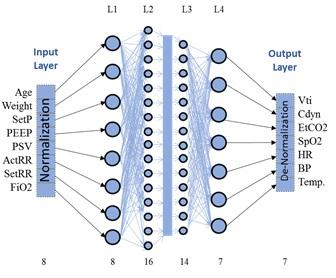              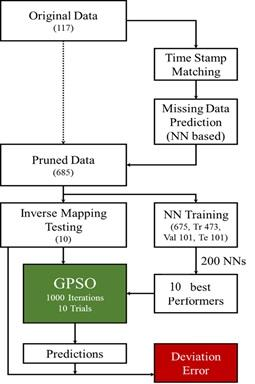

Fig 4(a). Neural Network Schema, mapping ventilator parameters and patient outcomes 4(b) Process flow used in our study

## 2.a Train NNs

We trained 200 of these ANNs and top ten best performers were selected for inverse mapping. Each of these NNs were trained with the same data set (ANN Generation) as presented in Table 1. However, Training, Validation and Testing data sets were randomized for each neural network. The top ten best performing NNs were selected based on low combined training, validation and testing errors. The error data of all the trained networks is presented in the bar graph as shown below.

A summary of process flow is presented in the following figure, starting from data acquisition to pruning, NN training, selection and inverse mapping processes.

***Separate Testing Data***

load('predData.mat')
testDataPts=10;
szC=size(combinedMatPred);
lcs=randi(szC(1),1,testDataPts);
testData=combinedMatPred(lcs,:)
trainData=combinedMatPred;
trainData(lcs,:)=[];
inputData=trainData(:,1:8);
targetData=trainData(:,9:15);
save('dataForExperiments');

**Train 200 Nets and select the best**

clc;
clear all;
close all;
load('dataForExperiments.mat');
totalNets=200;
bestNets=10;
hiddenLayerSize = [8 16 14];



if ~exist("bestNNs", 'dir')
       mkdir("bestNNs")
end

curfld=pwd;
destPth=strcat(curfld,'\bestNNs');

for i=1:totalNets
    disp(strcat('runninNet:',num2str(i)))
    netPerform(i)=trainNetFunction(inputData,targetData,i,hiddenLayerSize);
    netPerform(i)
end

clc;
clear;
load('dataAfterNNTrain.mat');
[sortPerform locs]=sort(netPerform);
bestOnes=locs(1:bestNets);
bestPerform=sortPerform(1:bestNets);
ctr=0;
% for j=bestOnes
%     ctr=ctr+1;
%     movefile(strcat('net_',num2str(j),'.m'),strcat(destPth,'\Net_',num2str(ctr),'.m'));
% end

f1=figure;bar(netPerform);
hold on; bar(bestOnes,bestPerform,'r');
label('all','','NN Number','Performance (Total Error)');
% saveas(f1,'BestNNs','fig')
% saveas(f1,'BestNNs','png')




% This can be executed
% open('nnPerformance.fig')

**Inverse Mapping**

Inverse mapping procedure has been used in providing solutions to many real world engineering problems, especially in inverse kinematics problems, where joint parameters need to be determined for a given position of the end effector in the space [8, 9, 10]. In this procedure, the right input parameters for the NNs are determined for a desired output. This procedure is different in its performance for the same network trained in an inverse way by the fact that many combinations of inputs lead to the same final output. This is similar to solving inverse kinematics problem in manipulators, where a final position of the end effector can be achieved by many possible combination of joint parameters. Another application of inverse mapping was by Pidaparti et al., [15] applied on the structural integrity problem of aging air crafts, where strength, corrosion and fatigue properties of the material was analyzed. 

The flow diagram for inverse mapping algorithm is presented in figure 7 with GPSO applied for input correction. The algorithm starts with some random values of inputs to the neural network and the output of the network is compared with the targets or desired values. Fitness for each of the members in the swarm are computed from equation 4. This is similar to the gradient descent algorithm on NNs. 

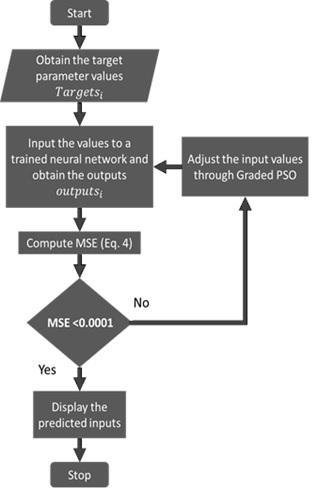                         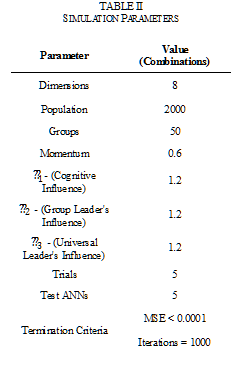

*Fig. 5(a) Inverse Mapping of NNs with GPSO process flow. 5(b) Simulation Parameters*

% This takes very long time as this is a simulation segment. And cant be executed without executing the previous segments
clc;
clear all;
close all;
load('dataAfterNNTrain.mat');
addpath('/bestNNs');
gpso.pop=200;
gpso.omega=0.8;
gpso.groups=5;
gpso.pbest=1.2;
gpso.gbest=1.2;
gpso.ubest=1.2;

trls=100;
inpSz=8;
iterations=100;
varRange.min=min(combinedMatPred);
varRange.max=max(combinedMatPred);



% 
% for dataSt=1
%     tic
%     dataSt
%     testSample=testData(dataSt,:);
%     testInp=testSample(1,1:8);
%     testOutp=testSample(1,9:end);
%     for nts=1:1    % This is a parallel loop. Check parellel processing tool box before execution
%         nts
%         [inpPreds simData]=runGPSO(gpso,nts,testOutp,varRange,trls,inpSz,iterations,testInp(1:2));   % Call optimizer function here
%         inpPreds=inpPreds'
%        Net{nts}=perfEval(nts,inpPreds,testInp,testOutp,simData);
%     end
%      Nets=Net;
%      save(strcat('dataSt_',num2str(dataSt)),'Nets','-v7.3')
%      
%     clear Nets inpPreds simData test Sample testInp testOutp;
%     toc
% end
% save('simulatedData','simulationData');


for dataSt=1
    tic
    dataSt
    testSample=testData(dataSt,:);
    testInp=testSample(1,1:8);
    testOutp=testSample(1,9:end);
    for nts=1:1
        nts
        [finalStats]=RunGPSO(gpso,nts,testOutp,varRange,trls,inpSz,iterations,testInp(1:2));
        Nets{nts}=finalStats;
    end
    save(strcat('dataSt_',num2str(dataSt)),'Nets','-v7.3')
end



ntNo=1;

for trials=1:trls
    finalVals(trials,:)=Nets{ntNo}{trials}.finalUniversalLeaderValues;
end



## Results

Sample performance graphs for MSE of Outputs over iterations, for a couple of test cases is presented in figures 7- 8. For test case 1 the variation of the mechanical ventilation parameters over iterations is presented in the following code. The graphs presented in figures 7-10 are only samples of the tests performed over the 10 test cases separated initially. A summary for test case -1 with all parameter combinations is presented in table 3. Also, the performance of five NNs on inverse mapping is presented in figures 10(a) and 10(b). The NNs with the best performance for a test group is highlighted in red and the corresponding parameter values are indicated on the top for each test set. 

% This can be executed for viewing the graphs. The graph data was directly opened as the related commands were originally executed in a command line
clc;
clear all;
close all;
for i=1:10
    fileStr=strcat('data',num2str(i),'.bmp');
    img=imread(fileStr);
    figure;imshow(img);
end


A comparision bar graph is presented in the following code.

% This can be executed
clc;
clear all;
load('bargraphDataOutputs.mat');
figure;
x=1:4;
ctr=0;
[ha, pos] = tight_subplot(4,10,[0 0],[.1 .01],[.01 .01]) 
color1=[255, 84, 0]./255;
color2=[62, 188, 0]./255;
color3=[0, 131, 255]./255;
color4=[0.9 0.9 0.9];
%%
ylsm=[447	63	107	77];

intrvl=[50 10 20 20];
%ylbl={'Set P','PEEP','PSV','RR','FiO2','MSE'};
ylbl={'Vti','EtCO2','SpO2','MSE'};
for j=1:4
    for i=1:10
        ctr=ctr+1;
        axes(ha(ctr));
        dum=prnData{i}';
        dum1=dum(j,:)';
       % dum2=sttData{i};
        bar(3,dum1(1),'FaceColor',(color3),'EdgeColor',(color3));hold on;
        bar(2,dum1(2),'FaceColor',(color2),'EdgeColor',(color2));
        bar(1,dum1(3),'FaceColor',(color1),'EdgeColor',(color1));
    %    plot([-100 100],[dum2(3)+dum1(1) dum2(3)+dum1(1)],':k');
     %  plot([-100 100],[dum1(1)-dum2(3) dum1(1)-dum2(3)],':k');
        ylim([0 ylsm(j)]);
        xlim([0.25 3.75]);
        
      %  rectangle('Position',[3.75,dum2(1),1,max(dum2(2)-dum2(1),dum1(1)-dum2(1))]);
         if i~=1
      set(ha(ctr),'yticklabel',[],'xtick',[]);
         end
        if i==1
        set(ha(ctr),'ytick',0:intrvl(j):ylsm(j),'xtick',[]);
        
        end
        if i==10
             set(gca,'yaxislocation','right');
        ylabel(ylbl{j});
        end
        if j==4
            xlabel(strcat('Set-',num2str(i)));
            set(ha(ctr),'Color',color4);
        end
        
       
        grid on; grid minor;
    end
end
axes(ha(1));
legend('Averaget','Best','Target');


*  open summary sheet in windows*

winopen finalResults.xlsx

*  Alternate graphs for the data - Flower plots*

% These are experimental graphs. This code was represented exclusively for this work.
clc;
%close all;
clear;
dum1=xlsread('finalResults.xlsx');

dataSep=dum1(:,7);
dataMeans=dataSep(3:7:end);
dataBest=dataSep(5:7:end);
dataTarget=dataSep(6:7:end);

dMTs=0:36:360-36;
dMTe=12:36:360;
dBTs=12:36:360;
dBTe=24:36:360;
dTTs=24:36:360;
dTTe=36:36:360;
bckGrnds=0:72:360-72;
bckGrnde=36:72:360;
bckGrnds1=bckGrnde;
bckGrnde1=72:72:360;
rdsBck=ones(1,length(bckGrnds))*max([dataMeans' dataBest' dataTarget'])+5;
fg=figure;

generatePlot(bckGrnds,bckGrnde,rdsBck,[1,1,1]*0.8);
generatePlot(bckGrnds1,bckGrnde1,rdsBck,[1,1,1]*0.5);
generatePlot(dMTs,dMTe,dataMeans,[0,255,178]./255);% Color as the last argument
generatePlot(dBTs,dBTe,dataBest,[128,145,232]./255);
generatePlot(dTTs,dTTe,dataTarget,[128,200,232]./255);


%% Plot Circles
a=(0:360).*(pi/180);
b=length(a);
maxRadius=max([dataMeans' dataBest' dataTarget']);
cirRs=5:5:maxRadius;
for i=1:length(cirRs)
    polarplot((0:360).*(pi/180),ones(1,b).*cirRs(i),':k','LineWidth',0.75);
end

% quads=0:90:360;
% 
% polarplot(quads,ones(1,length(quads))*maxRadius,'k');
% 


## **Conclusions**

In our current work, inverse mapping on artificial neural networks was applied in predicting the mechanical ventilator parameters. A novel, algorithm GPSO proposed in our previous work was applied as an optimizer in inverse mapping. Extensive simulations were run in understanding the behavior of GPSO and also in arriving at better prediction values for MVs. It can be observed from figures 7, 8 9 and 10 that the GPSO algorithm was working towards searching for a better optimum through multiple groups (50 groups). The optimization was with respect to the output MSE computed between the targets and the computed outputs for predicted inputs of the neural networks. 

The bar graphs presented in figure 10 are of best performers, and average of parameters across all the iterations for 10 trials on each NN set. It can be noticed that the MSEs of outputs in 10 (b) are very low for most of the cases for the best performer combination. This means that the inverse mapper was successful in finding the best combinations for converging the outputs of the NNs towards the targets. However, these best values making the output MSEs zero may not be the desired values. This is evident form the input MSEs, which show higher values for the corresponding best performers. This means that the inverse mapper was finding a different parameter combination which was also minimizing the output MSEs. Our designed GPSO is also expected to find other combinations of parameters and hence, we also considered the average of input data as possible values of the parameters, which evidently showed lower input MSEs than the MSEs from the best performers as shown in 10(a). 

Arriving at a conclusive evidence on best parameter combinations for GPSO was not possible for this problem as the NN functions are highly non-linear and hence finding a perfect global optimum is next to impossible. However, this can be enhanced by improving the training and selection process of ANNs. Our observations suggested that increasing the amount of data points with more percentage of healthy patients can further stabilize the ANNs. The data utilized for our study currently is largely from unhealthy patients as healthy patients usually are not observed on mechanical ventilators. 

# References

*[1]           J. J. Marini, "Mechanical ventilation: past lessons and the near future," CRITICAL CARE, vol. 17, 2013.*

*[2]           K. Hopper and L. L. Powell, "Basics of Mechanical Ventilation for Dogs and Cats," Veterinary Clinics of North America: Small Animal Practice, vol. 43, pp. 955-969, 7/1/July 2013 2013.*

*[3]           R. S. Campbell and B. R. Davis, "Pressure-controlled versus volume-controlled ventilation: does it matter?," Respiratory Care, vol. 47, pp. 416-424, 2002.*

*[4]           A. Koenig, "The ABCs of Mechanical Ventilation," 2011, pp. 504-506.*

*[5]           F. P. Akbulut, E. Akkur, A. Akan, and B. S. Yarman, "A decision support system to determine optimal ventilator settings," BMC MEDICAL INFORMATICS AND DECISION MAKING, vol. 14, 2014.*

*[6]           D. Nelson, J. Strickland, and T. Jannett, "Simulation of fuzzy control for management of respiratory rate in assist-control mechanical ventilation," 1997, pp. 1104-1107.*

*[7]           F. T. Tehrani, "A new decision support system for mechanical ventilation," Conference Proceedings: ... Annual International Conference Of The IEEE Engineering In Medicine And Biology Society. IEEE Engineering In Medicine And Biology Society. Annual Conference, vol. 2007, pp. 3569-3572, 2007.*

*[8]           S. Tejomurtula and S. Kak, "Inverse kinematics in robotics using neural networks," Information Sciences, vol. 116, p. 147, 1999.*

*[9]           D. DeMers and K. KreutzDelgado, "Canonical parameterization of excess motor degrees of freedom with self-organizing maps," IEEE TRANSACTIONS ON NEURAL NETWORKS, vol. 7, pp. 43-55, 1996.*

*[10]         D. DeMers, and Kreutz-Delgado, K.,, "Inverse Kinematics of Dexterous Manipulators," in Neural Systems for Robotics, O. O. a. P. v. d. Smagt, Ed., ed New York: Academic Press, 1997, pp. 75-116.*

*[11]         J. Kennedy and R. Eberhart, "Particle Swarm Optimization," 1995, pp. 1942-1948.*

*[12]         E. Parsopoulos Konstantinos, PARTICLE SWARM OPTIMIZATION AND INTELLIGENCE ADVANCES AND APPLICATIONS: Information Science Reference, 2010.*

*[13]         W.-D. Chang, "A modified particle swarm optimization with multiple subpopulations for multimodal function optimization problems," Applied Soft Computing, vol. 33, pp. 170-182, 8/1/August 2015 2015.*

*[14]         G. G. Yen and M. Daneshyari, "DIVERSITY-BASED INFORMATION EXCHANGE AMONG MULTIPLE SWARMS IN PARTICLE SWARM OPTIMIZATION," International Journal of Computational Intelligence & Applications, vol. 7, pp. 57-75, 03// 2008.*

*[15]         W. Elshamy, H. M. Emara, and A. Bahgat, "Clubs-based Particle Swarm Optimization," 03/01/ 2013.*

*[16]         Sanjay, Sarma OV, and Ramana M. Pidaparti. "Graded Particle Swarm Optimization (GPSO)." International Conference on Robotics: Current Trends and Future Challenges (RCTFC),. IEEE, 2016.*